# Mobility framework

Here we define the mobility by body morphing quadrupedal systems through the computation of reachable sets in $\mathit{SE}(2)$ (fiber or position space) as a function of periodic trajectories in limb actuation space (base or shape space).

addpath 'Data'\ 'Utility Functions'\;

## Basic setup

### Contact State Information

We need some general information of two-beat gaits and the corresponding level-2 submanifolds. We compute that below:

% all lvl2 contact submanifolds
cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];
% initialize a array as many rows as `cs' to count if all contact states
% are paired up
cs_counter = zeros(size(cs, 1), 1);
% collect the location pairs in an array
cs_IdxFor2bGaits = double.empty(0, 2);
% increment the interation count
iter = 0;
% increment the array count
arrLoc = 0;
% iterate until all contact states are paired up
while sum(cs_counter) ~= numel(cs_counter)
    % increment the iteration
    iter = iter + 1;
    % proceed if this iteration is not already counted
    if isempty(find(cs_IdxFor2bGaits == iter, 1))
        % increment the array count
        arrLoc = arrLoc + 1;
        % create a cs_counter right now and assign the current row as we are
        % trying to find a pair for it
        cs_counterNow = zeros(size(cs_counter)); cs_counterNow(iter) = 1;
        % find its pair by checking all rows to see if none of the leg indices
        % overlap and that to current counter obtain 
        cs_counterNow = cs_counterNow + (  sum((cs == cs(iter, 1)) + (cs == cs(iter, 2)), 2) == 0  );
        % store the pair
        cs_IdxFor2bGaits(arrLoc, 1) = iter; 
        cs_IdxFor2bGaits(arrLoc, 2) = ...
            find(  sum((cs == cs(iter, 1)) + (cs == cs(iter, 2)), 2) == 0  );
        % add the current cs_counter to the global variable
        cs_counter = cs_counter + cs_counterNow;
    end
end
csString = {'Bound', 'Pace', 'Trot'}';
clear iter arrLoc cs_counter cs_counterNow;
% save the data
if exist('Data\lvl2CSinfo.mat', 'file')
    save('Data\lvl2CSinfo.mat', "-append");
else
    save('Data\lvl2CSinfo.mat');
end

### Ploting parameters

Basic plotting parameters for to visualize the connection vector fields, the stratified panels, etc.

% all plotting information
% ... discretization, number of level-sets in contour plots
% ... custom colormaps
% ... stance phase and swing phase colors
dnum = 101;
skipV = 7.5;
sV = 10;
skipV = round((skipV/100)*2*floor(dnum/2)); sV = round((sV/100)*2*floor(dnum/2));
cLvl = 25;
cfLvl = 100;
fontscale = 1.25;
fA = 1.00;
cmap_custom = flipud([174,1,126;
           221,52,151;
           247,104,161;
           250,159,181;
           116,169,207;
           54,144,192])/255;
cmap_custom = interp1(linspace(0,100,size(cmap_custom,1)), cmap_custom, linspace(0,100,size(jet,1)));
jP = sqrt(cmap_custom(:,1).^2 + cmap_custom(:,2).^2 + cmap_custom(:,3).^2);
jS = 1.1;
cmap_custom = jS/max(jP)*repmat(jP,1,3).*cmap_custom; 
cmap_custom(cmap_custom > 1) = 1;
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255;
CUB = interp1(linspace(0,100,size(CUB,1)), CUB, linspace(0,100,size(turbo,1)));
col = (1/255)*[255,127,0;
                231,41,138;
                44,123,182;
                77,175,74;
                215,25,28;
                96,0,220;
                72,72,72];
col_backg = [255,255,255]/255;
bMorphCol_bid = flipud([158,1,66; % type: diverging, num data class: 11, right-end option
                        213,62,79;
                        244,109,67;
                        253,174,97;
                        254,224,139;
                        255,255,191;
                        230,245,152;
                        171,221,164;
                        102,194,165;
                        50,136,189;
                        94,79,162])/255;
bMorphCol_bid = interpColorAndCondition...
                            (...
        linspace(1, size(turbo, 1), size(bMorphCol_bid, 1))', ... % X
                            bMorphCol_bid, ... % V
                        (1:size(turbo, 1))'... % Xq
                            );
bMorphCol_unid = bMorphCol_bid(ceil(size(bMorphCol_bid, 1)/2):end, :);
edgeAlpha = 0.5;
lW_c = (1.0*10)/cLvl;
lW_Vector = (1.0/10)*skipV;
lW_V = (1.0/10)*sV;
lW_s = 2.0;
boxW = 1.2;
solidLS = '-'; % LS: linestyle
hashedLS = '--'; dotLS = ':';
itQ = 1:skipV:dnum;
iQ = 1:sV:dnum;
ai = linspace(-pi/2, pi/2, dnum); aj = ai; % manually defined limb discretization in a lvl-2 cs
xlimits = [ai(1) ai(end)]; ylimits = [aj(1) aj(end)]; [ai, aj] = meshgrid(ai, aj);
xtickval = xlimits(1):pi/2:xlimits(2); ytickval = xtickval;
xticklab = {'$$-\frac{\pi}{2}$$','$$0$$','$$\frac{\pi}{2}$$'}; yticklab = xticklab;
tickFS = 21*fontscale; labelFS = 21*fontscale; titleFS = 24*fontscale; cbarFS = 18*fontscale;
if exist('Data\nonslipPlottingParamsMobility.mat', 'file')
    save('Data\nonslipPlottingParamsMobility.mat', "-append");
else
    save('Data\nonslipPlottingParamsMobility.mat');
end

addpath 'Data'\ 'Utility Functions'\;

## Basic $\mathit{SE}(2)$ kinematics: Arbitrary body-morphing quadruped

Some variables to select the columns in the jacobian and $C_{xy}$ matrix to select the first two rows of the jacobian. The number of limbs is obviously $4$ and we also set the number of simplification steps to 10.

theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';
Cxy = [eye(2, 2), zeros(2, 1)];
numPos = 3; numLimbs = 4; numSteps = 10;

Moving forward, we shall define parameters that aid with body morphing analysis.

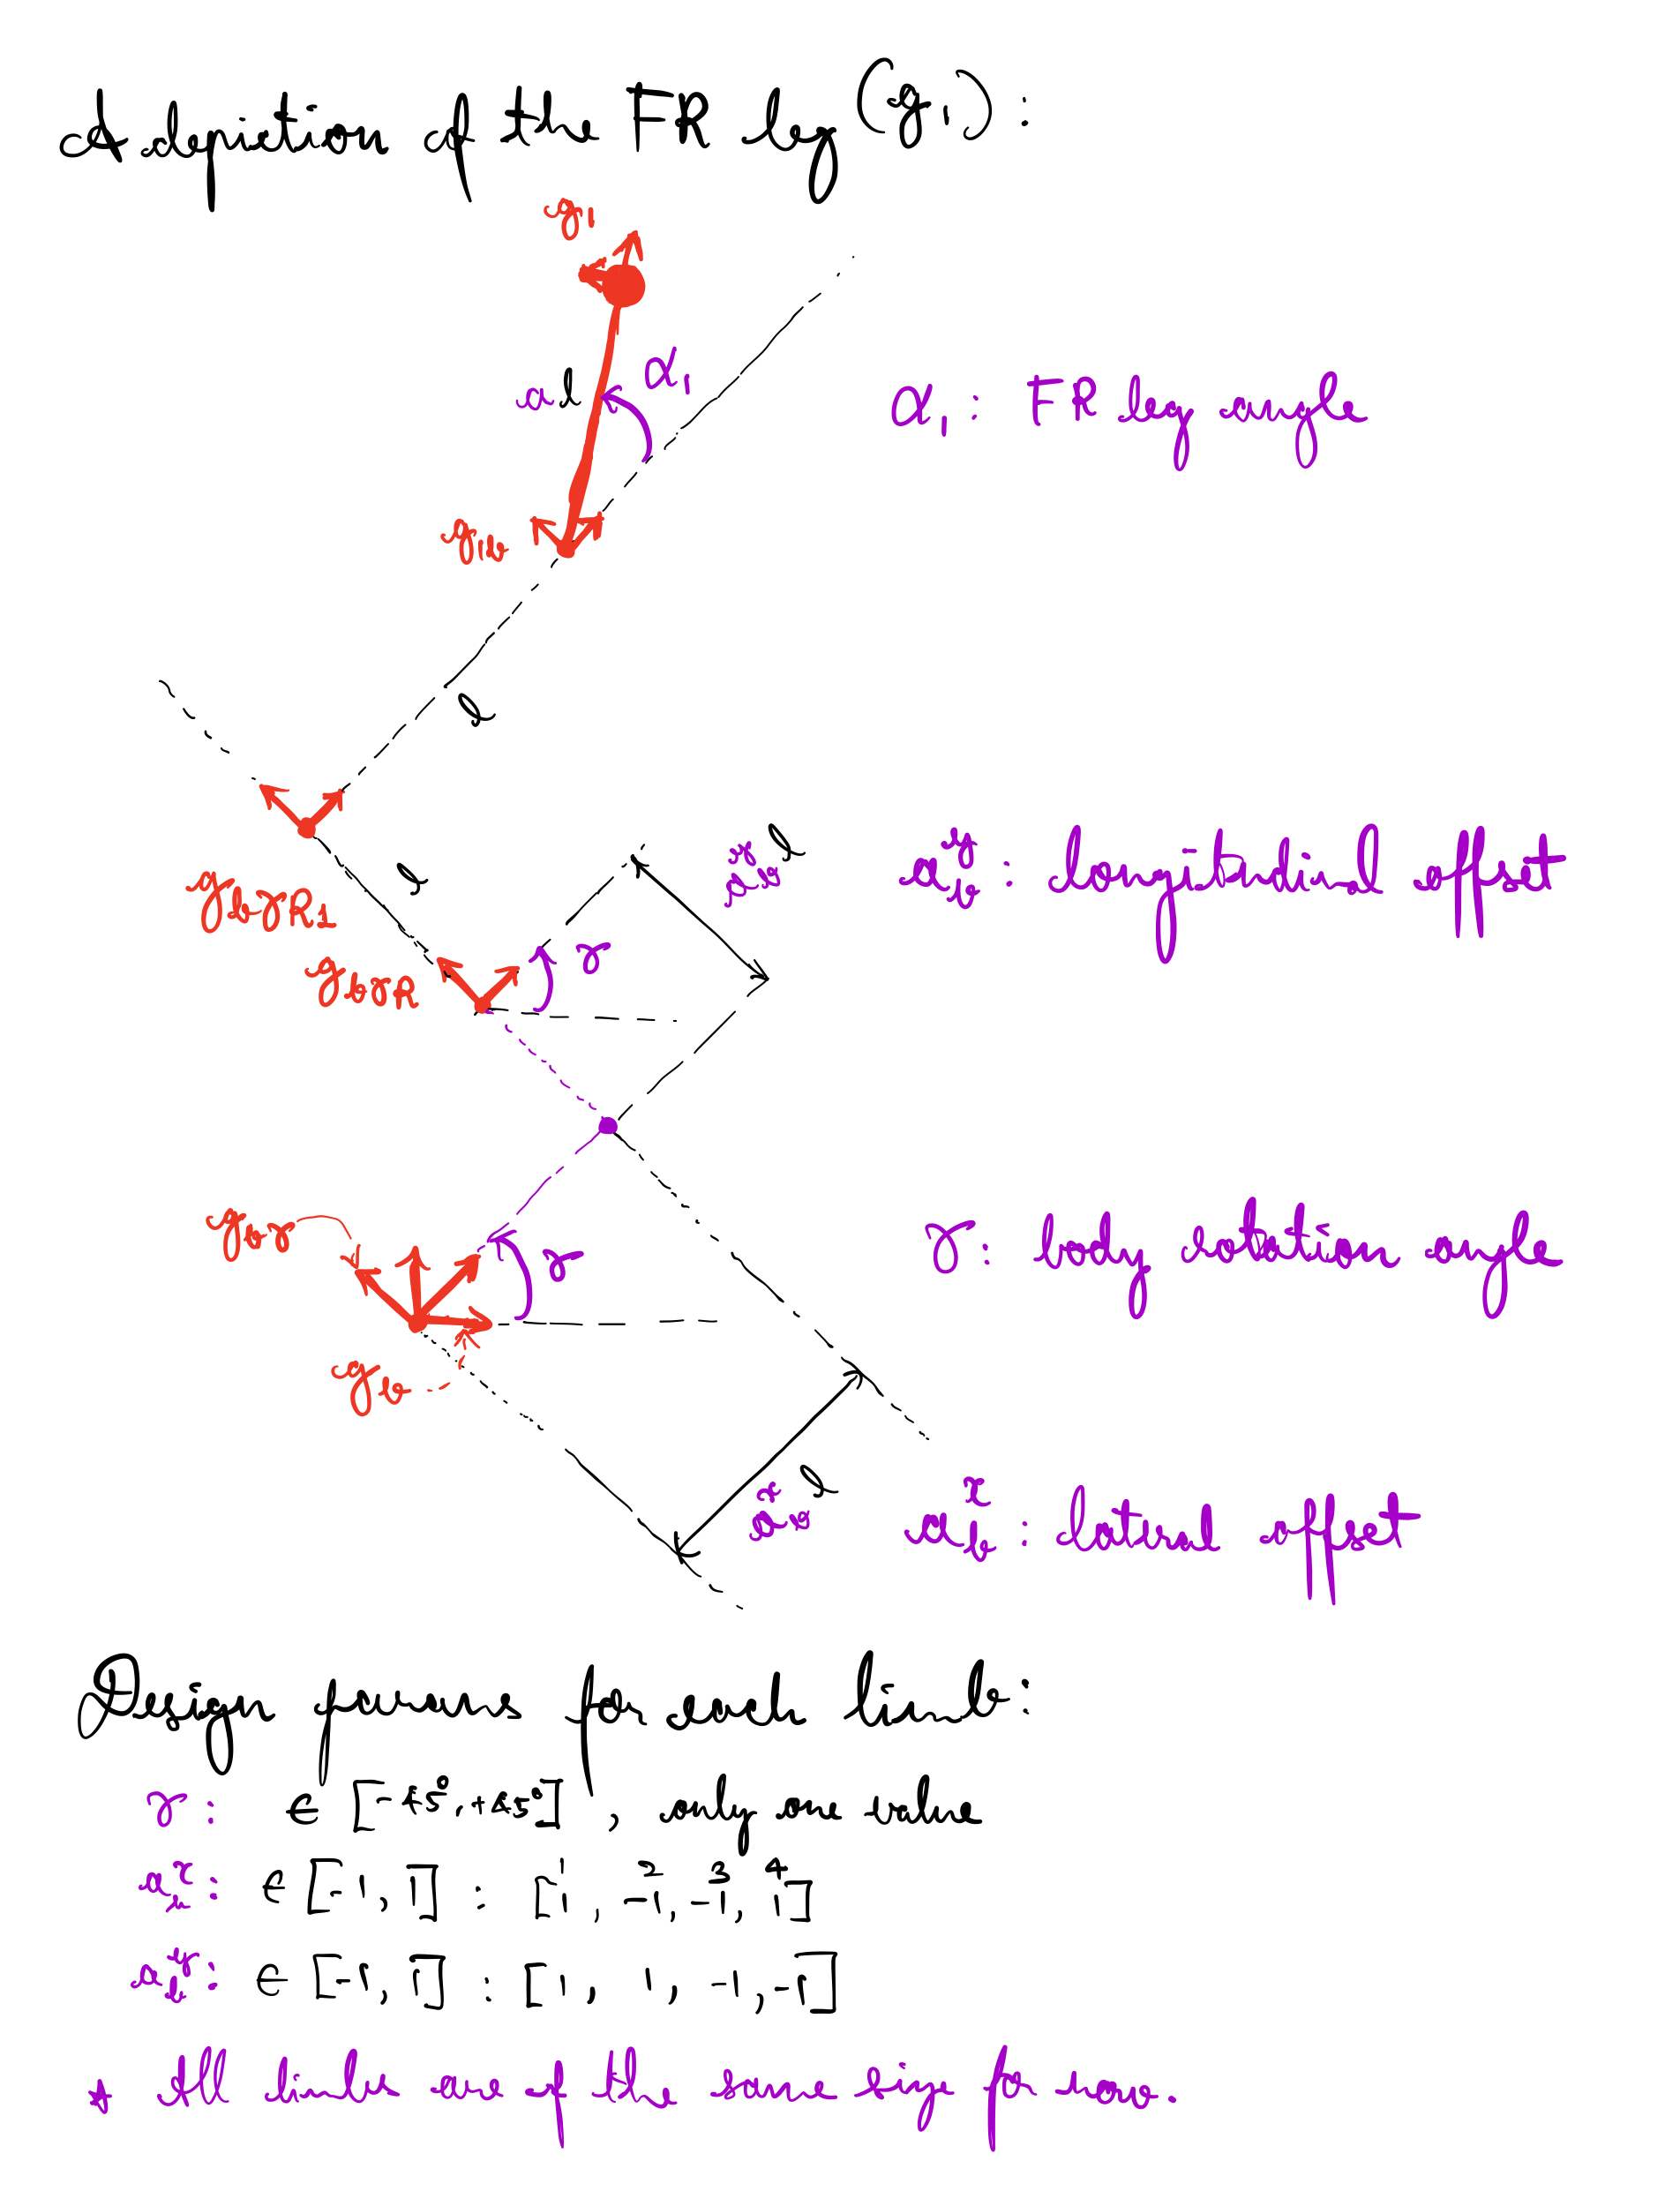

### Pin-joint parameter

Assuming there is a pin-joint at the body frame, $g_b$, we first rotate by $\gamma$ ($\in \left[ -\frac{\pi}{2}, \frac{\pi}{2} \right]$ radians) to enter the top half of the robot with the rotated frame coincident with the body frame, $g_{b \gamma}$. Also, load all the symbolic variables into appropriate arrays for function definitions later.

syms a_bX a_bY a l x y real % length and scaling vars
assume(a_bX >= 0 & a_bX <= 1); 
assume(a_bY >= 0 & a_bY <= 1); 
assume(a >= 0 & a <= 1); % limit the scaling vars to be between 0 and 1
syms theta gamma real % angle vars
syms alpha_1 alpha_2 alpha_3 alpha_4 real % limb angle vars (continuous shape space)
localSymVars = [a_bX a_bY a l gamma]; % ordered as scaling first, length next, and angles at the end
bodyPosVars = [x, y, theta];
h_e__b = [x, y, theta]'; fh_e__b = matlabFunction(h_e__b, "Vars", [x, y, theta]);
h_b__bRot = [0, 0, gamma]';
% ... limits and nominal values for the local symbolic parameters and shape
% ... variables
limbScalingParam = [0, 1, 1]; % limb scaling
bodyScalingParam = [-1, 1, 0]; % body occupancy scaling (for both longitudinal and lateral)
gammaParam = pi/4*[-1, 1, 0]; % body angle
limbAngleParam = pi/2*[-1, 1, 0]; % limb angle (continuous shape subspace)

Also, we need some flags to decipher the bottom-half of the body from the top-half so that we don't rotate the bottom-half. The indices for this row vector (from left to right) correspond to FR, FL, HR, and HL limbs. This will be the ordering moving forward for all 4-element arrays defining parameters to identify the hip joint for each limb.

bottomHalfFlag = [0, 0, 1, 1];

### Body occupancy parameter

Similarly, the $x$ and $y$ offsets of the hip frame have equal magnitude $l$ are also defined based on the quadrant of the limb's index; for example, the front right and hind left limbs have offsets $[l, l]$ and $[-l, -l]$ correspondingly.

The second parameter is the body occupancy parameter $a_b l$ that increases the hip joint offset in the $x$ and $y$-directions from the rotated body frame (for the upper half of the body identified using the '`bottomHalfFlag`' defined above). Note that we are not simultaneously changing occupancy and pin-joint articulation for now, but it is possible to do so for other systems of interest. We store this information in the form of a multiplier array and access it later. We provide a longitudinal offset as well with a similar scaling.

hip_offset = l*[ [1, -1, -1, 1]', [1, 1, -1, -1]', [0, pi, pi, 0]' ];
body_offset = [ a_bX*l*[1, -1, -1, 1]', a_bY*l*[1, 1, -1, -1]', zeros(4, 1) ];

Because we only have one continous limb angle, we can define the ith foot frame, $g_i$ from the ith hip joint, $g_{ib}$ as follows.

fh_ib__i = @(a, l, alpha) [a*l*[cos(alpha); sin(alpha)]; alpha]; % using upper case for the function

Because the limbs are laterally sprawled, we add $l$ length to the bounding box in the longitudinal direction past the hip joint from the body frame. Also, define a function to obtain this points more easily.

bound_box_corners = hip_offset(:, 1:2); 
bound_box_corners(:, 2) = bound_box_corners(:, 2) + hip_offset(:, 2);
Local_Box_Bounds_SE2 = ... % has to be rowise components
    @(t) [ [t(1), 0, -t(1), 0]; [0, t(2), 0, -t(2)]; zeros(1, numLimbs) ];
bodyLength = 4*l; % set the length of the body

### Compute transforms and Jacobians

Now, we iterate for each limb and obtain the $\mathit{SE}(2)$ transforms and jacobians to construct the system's nonslip kinematics using all the above definitions.

% local transforms
h_bRot__bOff = cell(numLimbs, 1); h_bOff__ib = cell(numLimbs, 1); h_ib__i = cell(numLimbs, 1); % main incremental transforms
z_b__bOff = cell(numLimbs, 1); fz_b__bOff = cell(numLimbs, 1); % translational displacement from 
h_b__i = cell(numLimbs, 1); % main transform from body frame to foot frame
h_bOff__boxCorners = cell(numLimbs, 1); % transforms to corners for plotting the bounding box
z_boxCorners = cell(numLimbs, 1); fz_boxCorners = cell(numLimbs, 1);
% transforms from SE(2) origin/identity
% ... these transforms help with visualizing the system in the position
% ... space
h_e__bOff = cell(numLimbs, 1);  h_e__ib = cell(numLimbs, 1); 
h_e__i = cell(numLimbs, 1); fh_e__i = cell(numLimbs, 1);
                               fh_e__ib = cell(numLimbs, 1);
z_ib__i = cell(numLimbs, 1); fz_ib__i = cell(numLimbs, 1);
h_e__boxCorners = cell(numLimbs, 1); fh_e__boxCorners = cell(numLimbs, 1);
% jacobians
J_b__i = cell(numLimbs, 1); J_ib__i = cell(numLimbs, 1); J_i = cell(numLimbs, 1);
% string to store the current shape vars
limbwiseShapeString = cell(numLimbs, 1);
% iterate and compute for each limb
% ... first the local transforms
% ... the the transforms from the group identity
% ... then compute the jacobians
for i = 1:numLimbs
    % current limb angle string components:
    limbwiseShapeString{i} = ['alpha_' num2str(i)];
    % local transforms
    h_bRot__bOff{i} = body_offset(i, :)';
    h_bOff__ib{i} = hip_offset(i, :)';
    h_ib__i{i} = fh_ib__i(a, l, eval(limbwiseShapeString{i}));
    % ... if it is the bottom half of the body, then we shouldn't rotate it by
    % gamma, so we check using our bottomHalfFlag
    if bottomHalfFlag(i)
        localTransformToOffsetArray = h_bRot__bOff{i};
        globalTransformToOffsetArray = [h_e__b, h_bRot__bOff{i}];
    else
        localTransformToOffsetArray = [h_b__bRot, h_bRot__bOff{i}];
        globalTransformToOffsetArray = [h_e__b, h_b__bRot, h_bRot__bOff{i}];
    end
    h_b__i{i} = simplify( ... % simplify the returned symbolic expression
        seqSE2transformation( ...
                    [localTransformToOffsetArray, ... % get to the offset body frame (local)
                    h_bOff__ib{i}, h_ib__i{i}] ... % typical transform through hip to foot
                             )...
                         , "Steps", numSteps);
    h_bOff__boxCorners{i} = Local_Box_Bounds_SE2(bound_box_corners(i, :));
    % transforms from identity
    h_e__bOff{i} = simplify( ...
        seqSE2transformation( globalTransformToOffsetArray ) ... % get to the offset body frame (global)
        , "Steps", numSteps);
    z_b__bOff{i} = simplify( h_e__bOff{i} - h_e__b, "Steps", numSteps );
    fz_b__bOff{i} = matlabFunction(z_b__bOff{i}, "Vars", [localSymVars, bodyPosVars]);
    h_e__ib{i} = simplify( ...
        seqSE2transformation( [h_e__bOff{i}, h_bOff__ib{i}] ) ...
        , "Steps", numSteps);
    fh_e__ib{i} = matlabFunction(h_e__ib{i}, "Vars", [localSymVars, bodyPosVars]);
    h_e__i{i} = simplify( ...
        seqSE2transformation( [h_e__ib{i}, h_ib__i{i}] ) ...
        , "Steps", numSteps);
    fh_e__i{i} = matlabFunction(h_e__i{i}, "Vars", ...
        [localSymVars, bodyPosVars, eval(limbwiseShapeString{i})]);
    z_ib__i{i} = simplify( h_e__i{i} - h_e__ib{i}, "Steps", numSteps);
    fz_ib__i{i} = matlabFunction(z_ib__i{i}, "Vars", ...
        [localSymVars, bodyPosVars, eval(limbwiseShapeString{i})]);
    h_e__boxCorners{i} = sym(nan(size(h_bOff__boxCorners{i}))); 
    for j = 1:size(h_bOff__boxCorners{i}, 2) % iterate over each corner
        h_e__boxCorners{i}(:, j) = ...
            simplify( ...
        seqSE2transformation( [h_e__bOff{i}, h_bOff__boxCorners{i}(:, 1:j)] ) ...
        , "Steps", numSteps); % compute the corners: {BR, TR, TL, BL (start)}
    end
    temp = [h_e__bOff{i}, h_e__boxCorners{i}]; 
    z_boxCorners{i} ... % get the displacements: BL->BR, BR->TR, TR->TL, TL->BL
        = simplify(temp(:, 2:end) - temp(:, 1:end-1), "Steps", numSteps); 
    fz_boxCorners{i} = matlabFunction(z_boxCorners{i}, "Vars", [localSymVars, bodyPosVars]);
    h_e__boxCorners{i} ... % move the corners around to: {BL (start), BR, TR, TL}
        = circshift(h_e__boxCorners{i}, 1, 2); % now we can plot the boxes using quivers
    fh_e__boxCorners{i} = matlabFunction(h_e__boxCorners{i}, "Vars", [localSymVars, bodyPosVars]);
    % obtain the jacobians
    J_b__i{i} = simplify(adj_adjinv_SE2(h_b__i{i}, -1), "Steps", numSteps); % keep all the columns as body undergoes a twist
    J_ib__i{i} = simplify(adj_adjinv_SE2(h_ib__i{i}, -1)*theta_sel, "Steps", numSteps); % select just rotation column
    % ... condition the full jacobian with pre and post zero columns for
    % ... hip joints that dont affect the current limb
    if i > 1 % if not the first limb, pad with zeros before the current limb's jacobian
        zerosPre = zeros(size(J_b__i{i}, 1), i-1);
    else
        zerosPre = [];
    end
    if i ~= numLimbs % if not the last limb, pad with zeros after
        zerosPost = zeros(size(J_b__i{i}, 1), numLimbs-i);
    else
        zerosPost = [];
    end
    J_i{i} ... % get the full jacobian and clear temp vars
        = [J_b__i{i}, zerosPre, J_ib__i{i}, zerosPost]; 
    clear globalTransformToOffsetArray zerosPre zerosPost; 
end

The general convention in naming variables: 1) stance phases during a two-beat gait are index 'i' and 'j'; 2) within a stance phase, the feet instance as indexed 'm' and 'n'.

Now, we are ready to compute the rest of the terms. Let's iterate over each level-2 contact state: 

- to compute the the translational transform from foot frame $h_m$ to foot frame $h_n$ involved in the current stance phase $h^{t}_{\frac{n}{m}} = C_{xy} \, h_{\frac{n}{m}}$ where $C_{xy}$ is the selection matrix defined earlier

- we compute the squared inter-leg distance $F_i$ by taking the dot product of $h^{t}_{\frac{n}{m}}$ with itself

- a string to store the names of shape variable involved in the current level-2 submanifold as strings

- compute the full pfaffian constraint and split it up into the body and shape submatrices

- local connection for each level-2 submanifold: full version that acts on all limb angles and a truncated version with just the nonzero columns

- stratified panels or the discrete curvature functions between the stance and swing phase of a subgait cycle 

- obtain the associated first-order lie-bracket between the stratified panels of stance phases 'i' and 'j' involved in each two-beat gait cycle.

% load contact state information
load("Data\lvl2CSinfo.mat");
% init
hT_m__n = cell(size(cs, 1), 1);
F_i = cell(size(cs, 1), 1); fF_i = cell(size(cs, 1), 1);
shapeSubmString = cell(size(cs, 1), 1);
 delAlpha_NS = cell(size(cs, 1), 1);  delAlpha_S = cell(size(cs, 1), 1);
fdelAlpha_NS = cell(size(cs, 1), 1); fdelAlpha_S = cell(size(cs, 1), 1);
pfaff = cell(size(cs, 1), 1); pfaffB = cell(size(cs, 1), 1); pfaffR = cell(size(cs, 1), 1);
Afull_i = cell(size(cs, 1), 1); A_i = cell(size(cs, 1), 1); fA_i = cell(size(cs, 1), 1);
dz_i = cell(size(cs, 1), 1); fdz_i = cell(size(cs, 1), 1);
dQ_i = cell(size(cs, 1), 1); fdQ_i = cell(size(cs, 1), 1);
for i = 1:size(cs, 1)
    % ... get the strings needed to evaluate expressions and create
    % ... functions: locoSubmString
    shapeSubmString{i} = {eval(['alpha_' num2str(cs(i, 1))]), ...
                         eval(['alpha_' num2str(cs(i, 2))])};
    % ... squared inter-leg distance
    hT_m__n{i} = simplify(Cxy*(h_b__i{cs(i, 2)} - h_b__i{cs(i, 1)}), "Steps", numSteps);
    F_i{i} = simplify(hT_m__n{i}'*hT_m__n{i}, "Steps", numSteps);
    fF_i{i} = matlabFunction(F_i{i}, 'Vars', ...
        [localSymVars, shapeSubmString{i}{1}, shapeSubmString{i}{2}]);
    % ... slip and nonslip coordinates from squared inter-leg distance
    % ... ... these are unit vector fields in the directions along and
    % ... ... perpendicular to the gradient of F_i
    delAlpha_S_now = gradient(F_i{i}, ...
        [shapeSubmString{i}{1}, shapeSubmString{i}{2}]); % get gradient
    delAlpha_S_now ...
        = simplify(delAlpha_S_now/norm(delAlpha_S_now), "Steps", numSteps); % normalize slipping coords
    delAlpha_NS_now ...
        = simplify(Cxy*round(rot_SE2(-pi/2))*Cxy'*delAlpha_S_now, "Steps", numSteps); % obtain nonslip coords
    delAlpha_S{i} = delAlpha_S_now;
    delAlpha_NS{i} = delAlpha_NS_now; % assign
    fdelAlpha_S{i} = matlabFunction(delAlpha_S_now, 'Vars', ...
        [localSymVars, shapeSubmString{i}{1}, shapeSubmString{i}{2}]);
    fdelAlpha_NS{i} = matlabFunction(delAlpha_NS_now, 'Vars', ...
        [localSymVars, shapeSubmString{i}{1}, shapeSubmString{i}{2}]);
    % ... pfaffian constraints and local connections
    pfaff{i} = [Cxy*J_i{cs(i, 1)}; Cxy*J_i{cs(i, 2)}];
    pfaffB{i} = pfaff{i}(:, 1:3); pfaffR{i} = pfaff{i}(:, 4:end);
    Afull_i{i} = simplify(...
        ( transpose(pfaffB{i})*pfaffB{i} )\transpose(pfaffB{i})*pfaffR{i}...
        , "Steps", numSteps);
    A_i{i} = Afull_i{i}(:, cs(i, :));
    fA_i{i} = matlabFunction(A_i{i}, 'Vars', ...
        [localSymVars, shapeSubmString{i}{1}, shapeSubmString{i}{2}]);
    % ... stratified panels
    dz_i{i} = simplify(A_i{i}*delAlpha_NS{i}, "Steps", numSteps);
    fdz_i{i} = matlabFunction(dz_i{i}, 'Vars', ...
        [localSymVars, shapeSubmString{i}{1}, shapeSubmString{i}{2}]);
    % ... configuration velocity or horizontal lift of the connection
    dQ_i{i} = simplify( ...
                [rot_SE2(theta), zeros(3, 2); ...
                    zeros(2, 3), eye(2, 2)]*...
                    [dz_i{i}; delAlpha_NS{i}]...
                , "Steps", numSteps);
    fdQ_i{i} = matlabFunction( dQ_i{i}, "Vars", ...
        [localSymVars, bodyPosVars, ...
        shapeSubmString{i}{1}, shapeSubmString{i}{2}] );
end
clear i j;
% save the data
if exist('Data\nonslipQuadMobility.mat', 'file')
    save('Data\nonslipQuadMobility.mat', "-append");
else
    save('Data\nonslipQuadMobility.mat');
end

% add the required folders to path
addpath 'Data'\ 'Utility Functions'\; 
% gait and contact information with plotting parameters
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
% load the system specific information for the mobility analysis
load('Data\nonslipQuadMobility.mat');
% Set the default interpreter before plotting to latex
%%%% https://www.mathworks.com/matlabcentral/answers/346436-how-to-use-latex-interpreter-for-xticklabels
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

## Geometric Mechanics: Rigid quadruped

### Setup basic parameters

This analysis should be similar to Paper 2 and is only done as validation step to verify the kinematics. Because we are working with trotting gaits

% choose the two stance phases involved in the trot gait
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :);

% we choose to remove a 'F_prctRm' percentage of the F-range close to the
% infimum of F
F_prctRm = 15;

% local parameters that define the system's SE(2) kinematics
% ... we will add 'n' prefix to the numeric vars to differentiate
% ... them from their symbolic counterparts
na_bX = bodyScalingParam(end); % nominal body occupancy in X and Y
na_bY = bodyScalingParam(end); 
na = limbScalingParam(end); % nominal limb length
nl = 1; % nominal length parameter-- this is fixed
ngamma = gammaParam(end); % nominal lateral body angle

% limb angle positions
% ... they together form the continuous shape subspace
% ... we define a random position to plot the robot and the nominal
% ... position for all of them
nalpha = rand(4, 1, "double")*(limbAngleParam(2) - limbAngleParam(1)) ...
    + limbAngleParam(1);
nalpha0 = limbAngleParam(end);

% specify the SE(2) location for the body frame
nx = 1; ny = 1; ntheta = pi/4;

% robot configuration plotting parameters
% ... some of these terms are defined based on the body length, so its
% ... defined locally as 4xl-- we need to convert this from symbolic to
% ... numerical form using the nominal value
% ... the limits are defined manually here, maybe we can find a better way
% ... when simulating the system's trajectory
% ... color for the limbs during swing phase
bodyPlotThresh = 0.25*bodyLength*[-1 1];
limX = [0, nx+bodyLength];  limY = [0, ny+bodyLength]; 
limX = limX+bodyPlotThresh; limY = limY+bodyPlotThresh;
scal = 23.5*bodyLength/4; % everything symbolic
limX = double(subs(limX, l, 1)); limY = double(subs(limY, l, 1)); 
scal = double(subs(scal, l, 1)); % everything numeric now
scaleDraw = max([diff(limX),diff(limY)])/scal; % 23.5
lW = 1.2/scaleDraw; lW_r = 0.5/scaleDraw; lW_b = 0.8/scaleDraw;
lW_kq = 0.6/scaleDraw; lW_qf = 0.8/scaleDraw;
frame_scale = double(subs(0.10*bodyLength, l, 1));
circS = 75/scaleDraw;

% robot configuration
% ... compute the body render variables

% init, iterate, compute, and plot
F_sweep_NOW = cell(size(sIdx)); Flim_NOW = [inf, -inf];
FParam_NOW = cell(size(sIdx)); Fthresh_NOW = cell(size(sIdx));
stanceColor = cell(size(sIdx));

for i = 1:numel(sIdx)
    
    % ... squared inter-foot (stancing) distance: F
    % ... ... current function to compute F
    % ... ... get the sweep for the F scalar field
    % ... ... obtain the F parameter variable (stores limits and nominal
    % ... ... value)
    % ... ... remove 15% of the F-range about the singularity at the
    % ... ... infimum
    fFnow = fF_i{sIdx{i}};
    F_sweep_NOW{i} = fFnow(na_bX, na_bY, na, nl, ngamma, ai, aj);
    nalpha_mn_atInf_NOW = fmincon( ...
                @(x) fFnow(na_bX, na_bY, na, nl, ngamma, x(1), x(2)), ... % function setup
                nalpha0*ones(1, 2), [], [], [], [], ... % ic
                limbAngleParam(1)*ones(1, 2), limbAngleParam(2)*ones(1, 2), [],...
                optimoptions("fmincon", "Display", "none"));
    Finf_now = fFnow(na_bX, na_bY, na, nl, ngamma,...
        nalpha_mn_atInf_NOW(1), nalpha_mn_atInf_NOW(2));
    nalpha_mn_atSup_NOW = fmincon( ...
                @(x) fFnow(na_bX, na_bY, na, nl, ngamma, x(1), x(2)), ...
                nalpha0*ones(1, 2), [], [], [], [], ...
                limbAngleParam(1)*ones(1, 2), limbAngleParam(2)*ones(1, 2), [],... % find supremum location
                optimoptions("fmincon", "Display", "none"));
    Fsup_now = fFnow(na_bX, na_bY, na, nl, ngamma, nalpha_mn_atSup_NOW(1), nalpha_mn_atSup_NOW(2));
    F0_now = fFnow(na_bX, na_bY, na, nl, ngamma, nalpha0, nalpha0);
    if Finf_now < Flim_NOW(1)
        Flim_NOW(1) = Finf_now;
    end % updated the limits for plotting
    if Fsup_now < Flim_NOW(2)
        Flim_NOW(2) = Fsup_now;
    end
    FParam_NOW{i} = [Finf_now, Fsup_now, F0_now]; 
    FrangeNow = Fsup_now-Finf_now; Fthresh_NOW{i} = Finf_now + F_prctRm*FrangeNow;
    idxThresh = F_sweep_NOW{i} < Fthresh_NOW{i}; % locations below the recommended threshold
    F_sweep_NOW{i}(idxThresh) = nan(  size(F_sweep_NOW{i}(idxThresh))  ); % set these locations to nan
end

#### System visualization

#### F-contours

f = figure('units', 'pixels', 'position', [0 0 750 1200], 'Color','w'); set(f,'Visible','on');
t = tiledlayout(f, numel(sIdx), 1, "TileSpacing", "tight", "Padding", "tight");
for i = 1:numel(sIdx)
    ax = nexttile(t);
    contour(ax, ai, aj, F_sweep_NOW{i}, cLvl,'LineWidth',lW_c);
    axis equal tight; hold on; view(2);
    contour(ax, ai, aj, F_sweep_NOW{i}, Fthresh_NOW{i}*ones(1, 2), 'k--', 'LineWidth', lW_c+1);
    colormap(ax, cmap_custom); colorbar(ax, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
    set(get(ax, 'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
    title(ax, F_title_text, FontSize=titleFS);
    xticks(ax, xtickval); yticks(ax, ytickval);
    xticklabels(ax, xticklab);
    yticklabels(ax, xticklab);
    xlabel(ax, x_label_txt, FontSize=labelFS); ylabel(ax, y_label_txt, FontSize=labelFS);
    ax.XAxis.FontSize = tickFS; ax.YAxis.FontSize = tickFS; set(ax, 'Color', col_backg);
    xlim(ax, xlimits); ylim(ax, ylimits);
end

#### $\Delta \alpha_F^{||}$ vector field

f = figure('units', 'pixels', 'position', [0 0 600 600], 'Color','w'); set(f,'Visible','on');
ax = gca;
quiver(ax, ai(iQ,iQ), aj(iQ,iQ), dalpha_x_sweep(iQ,iQ), dalpha_y_sweep(iQ,iQ), 0.5,...
    'LineWidth', lW_V, 'Color', col(7, :));
axis equal tight; hold on; view(2);
quiver(ax, ai(iQ,iQ), aj(iQ,iQ), ndalpha_x_sweep(iQ,iQ), ndalpha_y_sweep(iQ,iQ), 0.5,...
    'LineWidth', lW_V, 'Color', col(5,:));
contour(ax, ai, aj, F_sweep_NOW, [Fval_thresh Fval_thresh], 'k--', 'LineWidth', lW_c+1);
set(get(ax,'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
title(ax, dpsi_title_text, 'Color', col(5, :), FontSize=titleFS);
xticks(ax, xtickval); yticks(ax, ytickval);
xticklabels(ax, xticklab);
yticklabels(ax, xticklab);
ax.XAxis.FontSize = tickFS; ax.YAxis.FontSize = tickFS; set(ax, 'Color',col_backg);
xlim(ax, xlimits); ylim(ax, ylimits);

#### local connection

f = figure('units', 'pixels', 'position', [0 0 2100 600], 'Color','w'); set(f,'Visible','on');
tiledlayout(1, 3, 'TileSpacing', 'tight', 'Padding', 'tight');
for i = 1:3
    ax = nexttile();
    quiver(ax, ai(itQ,itQ), aj(itQ,itQ), u_sweep{i}(itQ,itQ), v_sweep{i}(itQ,itQ),...
    'LineWidth', lW_Vector, 'Color', 'k');
    axis equal tight; hold on;
    %
    plot(q_t(:, 4), q_t(:, 5), 'LineWidth', lW_c+2, 'Color', col(5, :)); scatter( q_t(end, 4), q_t(end, 5), 100, col(5, :), "filled" ); % plot the trajectory
    plotpatharrow(ax, q_t(:, 4), q_t(:, 5), 0.05*pi, deg2rad(18), lW_c+2, col(5, :));
    %
    contour(ax, ai, aj, F_sweep_NOW, [Fval_thresh Fval_thresh], 'k--', 'LineWidth', lW_c+1);
    set(get(ax,'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
    title(ax, A_title_txt{i}, 'Color', 'k', FontSize=titleFS);
    xticks(ax, xtickval); yticks(ax, ytickval);
    xticklabels(ax, xticklab); yticklabels(ax, yticklab);
    ax.XAxis.FontSize = tickFS; ax.YAxis.FontSize = tickFS; 
    set(ax,'Color',col_backg);
    xlim(xlimits); ylim(ylimits);
end

#### stratified panels

f = figure('units', 'pixels', 'position', [0 0 2100 600], 'Color','w'); set(f,'Visible','on');
tiledlayout(1, 3, 'TileSpacing', 'tight', 'Padding', 'tight'); % 4
for i = 1:3 % :4
    ax = nexttile();
    contourf(ax, ai, aj, heat_sweep{i}, cfLvl, 'LineStyle', 'none', 'FaceAlpha', fA);
    axis equal tight; hold on;
    %
    plot(q_t(:, 4), q_t(:, 5), 'LineWidth', lW_c+2, 'Color', col(5, :)); scatter( q_t(end, 4), q_t(end, 5), 100, col(5, :), "filled" );
    plotpatharrow(ax, q_t(:, 4), q_t(:, 5), 0.05*pi, deg2rad(18), lW_c+2, col(5, :));
    %
    contour(ax, ai, aj, F_sweep_NOW, [Fval_thresh Fval_thresh], 'k--', 'LineWidth', lW_c+1);
    colormap(ax, CUB);
    switch i
        case 1
            clim(ax, lim_xy); % skipping the colorbar for the x heatmap since it is the same as y
        case 2
            clim(ax, lim_xy);
            colorbar(ax, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
        case 3
            clim(ax, lim_th);
            colorbar(ax, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
        otherwise
            % clim(ax, lim_Kap);
            colorbar(ax, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
    end
    set(get(ax,'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
    title(ax, dz_title_txt{i}, 'Color', 'k', FontSize=titleFS);
    xticks(ax, xtickval); yticks(ax, ytickval);
    xticklabels(ax, xticklab); yticklabels(ax, yticklab);
    ax.XAxis.FontSize = tickFS; ax.YAxis.FontSize = tickFS;
    xlim(xlimits); ylim(ylimits);
end

## Geometric Mechanics: Arbitrary body-morphing quadruped

### Setup basic parameters

### Geometric mechanics with varying lateral body angle

#### System visualization

#### F-contours

#### local connection

#### stratified panels

## Geometric Mechanics: Arbitrary body-morphing quadruped

### Setup basic parameters

### Geometric mechanics with varying body occupancy

#### System visualization

#### F-contours

#### local connection

#### stratified panels

addpath 'Data'\ 'Utility Functions'\; 
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat');
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

## Geometric Mechanics: Fixed 4CLARI

### Setup basic parameters

### Omni-directional sprawl setup

#### System visualization

#### F-contours

#### local connection

#### stratified panels

### Other sprawl setups

#### System visualization

#### F-contours

#### local connection

#### stratified panels

addpath 'Data'\ 'Utility Functions'\; 
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslipQuadMobility.mat');

set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Rigid quadruped case:

% some setup
% ... choosing submanifold index, nominal values for system parameters,
% ... position of the system offset from the origin
% ... convert body length to a numeric value
% ... choose randoming 
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :);
na_bX = bodyScalingParam(end); na_bY = bodyScalingParam(end);
na = limbScalingParam(end);
nl = 1; bodyLength = double(subs(bodyLength, l, nl));
ngamma = gammaParam(end);
F_prctRm = 15;
nalpha = rand(4, 1, "double")*(limbAngleParam(2) - limbAngleParam(1)) ...
    + limbAngleParam(1);
nalpha0 = limbAngleParam(end);
nx = bodyLength; ny = bodyLength; ntheta = pi/4;

% colors
% ... body color will be a version of gray (also swing phase color)
% ... limb colors will be their corresponding stance phase colors
bodyColor = col(end, :); limbSwingColor = bodyColor; originColor = bodyColor;
limbStanceColor = cell(1, numLimbs); % computed in the loop
paramColor = bodyColor; % this will change when the parameter is varying
                        % ... plot color for the robot configuration
                        % ... and the figure box

% body frame information
gbody = fh_e__b(nx, ny, ntheta);
bodyX = gbody'*x_sel; bodyY = gbody'*y_sel; bodyTh = gbody'*theta_sel;

% plot body frames
bodyFrameX = bodyX*ones(1, 2); bodyFrameY = bodyY*ones(1, 2);
bodyFrameU = x_sel'*rot_SE2(bodyTh)*Cxy'; bodyFrameV = y_sel'*rot_SE2(bodyTh)*Cxy';

% init, iterate, and compute
pltBodyX = []; pltBodyY = []; pltBodyU = []; pltBodyV = []; 
pltLimbX = []; pltLimbY = []; pltLimbU = []; pltLimbV = [];
pltLimbX0 = []; pltLimbY0 = []; pltLimbU0 = []; pltLimbV0 = []; 
footX = []; footY = [];
for i = 1:numLimbs
    % body to offset base
    pltBodyX = [pltBodyX, bodyX]; pltBodyY = [pltBodyY, bodyY]; 
    pltBodyU = [pltBodyU, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel];
    pltBodyV = [pltBodyV, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel];
    % offset base to the body corners
    pltBodyX = [pltBodyX, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel)'];
    pltBodyY = [pltBodyY, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel)'];
    pltBodyU = [pltBodyU, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel)'];
    pltBodyV = [pltBodyV, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel)'];
    % limb (actual position)
    pltLimbX = [pltLimbX, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel];
    pltLimbY = [pltLimbY, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel];
    pltLimbU = [pltLimbU, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha(i))'*x_sel];
    pltLimbV = [pltLimbV, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha(i))'*y_sel];
    % limb (origin)
    pltLimbX0 = [pltLimbX0, pltLimbX(i)]; pltLimbY0 = [pltLimbY0, pltLimbY(i)];
    pltLimbU0 = [pltLimbU0, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, 0)'*x_sel];
    pltLimbV0 = [pltLimbV0, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, 0)'*y_sel];
    % foot location
    footX = [footX, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha(i))'*x_sel]; 
    footY = [footY, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha(i))'*y_sel];
    % limb color based on stance
    limbStanceColor{i} = col(sIdx(logical(sum(cs(sIdx, :) == i, 2))), :);
end
pltInterLimbX = cell(1, numel(sIdx)); pltInterLimbY = cell(1, numel(sIdx)); 
pltInterLimbU = cell(1, numel(sIdx)); pltInterLimbV = cell(1, numel(sIdx));
stanceColor = cell(1, numel(sIdx));
for k = 1:numel(sIdx) % over the two lvl2-submanifolds
    m = cs(sIdx(k), 1); n = cs(sIdx(k), 2); % m and n limbs in stance
    pltInterLimbX{k} = footX(m); pltInterLimbY{k} = footY(m); % start at limb m
    pltInterLimbU{k} = footX(n)-footX(m); % vector from limb m to limb n
    pltInterLimbV{k} = footY(n)-footY(m);
    stanceColor{k} = col(sIdx(k), :); % assign the current stance phase color
end

% robot configuration plotting parameters
% ... some of these terms are defined based on the body length, so its
% ... defined locally as 4xl-- we need to convert this from symbolic to
% ... numerical form using the nominal value
% ... the limits are obtained from compute body and foot locations
% ... color for the limbs during swing phase
xPts = [0, pltBodyX, pltLimbX, footX]; yPts = [0, pltBodyY, pltLimbY, footY];
limX = [min(xPts), max(xPts)]; limY = [min(yPts), max(yPts)]; % compute the limits
bodyPlotThresh = 0.25*bodyLength*[-1 1]; % add a threshold
limX = limX+bodyPlotThresh; limY = limY+bodyPlotThresh; % augment the limits with threshold
scal = 30*bodyLength/4; % find a scaling-- you might have to play with this % multiplier values: 23.5 (thinner lines), 30 (better)
scaleDraw = max([diff(limX),diff(limY)])/scal;
lW = 1.2/scaleDraw; lW_r = 0.5/scaleDraw; lW_b = 0.8/scaleDraw;
lW_kq = 0.6/scaleDraw; lW_qf = 0.8/scaleDraw;
frame_scale = 0.10*bodyLength;
circS = 75/scaleDraw;

% init, iterate, compute, and plot
nalpha_mn_atInf = cell(size(sIdx));
nalpha_mn_atSup = cell(size(sIdx));
F_sweep = cell(size(sIdx)); % sweep of F for each cs
Flim = [inf, -inf];         % F limit for both cs
FParam = cell(size(sIdx));  % F limit and nominal value for each cs
Fthresh = cell(size(sIdx)); % lower bound for allowable shape psace in each cs
                            % ... based on 15% threshold above infimum of F
dzSweep = cell(size(sIdx)); % sweep dz for each cs and each component
dzParam = cell(size(sIdx)); % dz limits and nominal values for each cs
for i = 1:numel(sIdx)
    % ... squared inter-foot (stancing) distance: F
    % ... ... current function to compute F
    % ... ... get the sweep for the F scalar field
    % ... ... obtain the F parameter variable (stores limits and nominal
    % ... ... value)
    % ... ... remove 15% of the F-range about the singularity at the
    % ... ... infimum
    fFnow = fF_i{sIdx(i)};
    F_sweep{i} = fFnow(na_bX, na_bY, na, nl, ngamma, ai, aj);
    nalpha_mn_atInf{i} = fmincon( ...
                @(x) fFnow(na_bX, na_bY, na, nl, ngamma, x(1), x(2)), ... % function setup
                nalpha0*ones(1, 2), ... % ic at limb angle origin
                [], [], [], [], ... % no equality or inequality constraints
                limbAngleParam(1)*ones(1, 2), ...
                limbAngleParam(2)*ones(1, 2), ... % pi range, and pi/2 symmetric amplitude bounds
                [],... % no nonlinear constraints
                optimoptions("fmincon", "Display", "none"));
    Finf_now = fFnow(na_bX, na_bY, na, nl, ngamma,...
                    nalpha_mn_atInf{i}(1), nalpha_mn_atInf{i}(2));
    nalpha_mn_atSup{i} = fmincon( ... % find supremum location
                @(x) -fFnow(na_bX, na_bY, na, nl, ngamma, x(1), x(2)), ...
                nalpha0*ones(1, 2), ... % ic
                [], [], [], [], ... 
                limbAngleParam(1)*ones(1, 2), ...
                limbAngleParam(2)*ones(1, 2), ...
                [],... 
                optimoptions("fmincon", "Display", "none"));
    Fsup_now = fFnow(na_bX, na_bY, na, nl, ngamma, ...
                    nalpha_mn_atSup{i}(1), nalpha_mn_atSup{i}(2));
    F0_now = fFnow(na_bX, na_bY, na, nl, ngamma, nalpha0, nalpha0);
    if Finf_now < Flim(1)
        Flim(1) = Finf_now;
    end % updated the color limits for the F values-- one set of limits for both cs
    if Fsup_now > Flim(2)
        Flim(2) = Fsup_now;
    end
    FParam{i} = [Finf_now, Fsup_now, F0_now]; 
    FrangeNow = Fsup_now-Finf_now; Fthresh{i} = Finf_now + F_prctRm/100*FrangeNow;
    idxThresh = F_sweep{i} < Fthresh{i}; % locations below the recommended threshold
    F_sweep{i}(idxThresh) = nan(  size(F_sweep{i}(idxThresh))  ); % set these locations to nan
    % ... compute the stratified panels
    % ... ... current function to compute dz
    fdznow = fdz_i{sIdx(i)}; dzSweep{i} = cell(3, 1);
    dzRowiseComponents = fdznow(na_bX, na_bY, na, nl, ngamma, ...
        reshape(ai, [1, numel(ai)]), reshape(aj, [1, numel(aj)... % make the limb angle space row vectors
        ]));
    dzParam{i} = [min(dzRowiseComponents, [], 2), ...
                  max(dzRowiseComponents, [], 2), ...
                  fdznow(na_bX, na_bY, na, nl, ngamma, nalpha0, nalpha0)];
    switch i
        case 1
            transArrX = dzParam{i}(1, 1:2);
            transArrY = dzParam{i}(2, 1:2);
            rotArr    = dzParam{i}(3, 1:2);
        otherwise
            transArrX = [transArrX; dzParam{i}(1:2, 1:2)];
            transArrY = [transArrY; dzParam{i}(1:2, 1:2)];
            rotArr    = [rotArr, dzParam{i}(3, 1:2)];
    end
    for j = 1:size(dzRowiseComponents, 1)
        dzSweep{i}{j} = reshape(dzRowiseComponents(j, :), size(ai));
    end
end


ans =

     []


ans =

     []



[transLimits, rotLimits] = se2limits(transArrX, transArrY, rotArr);

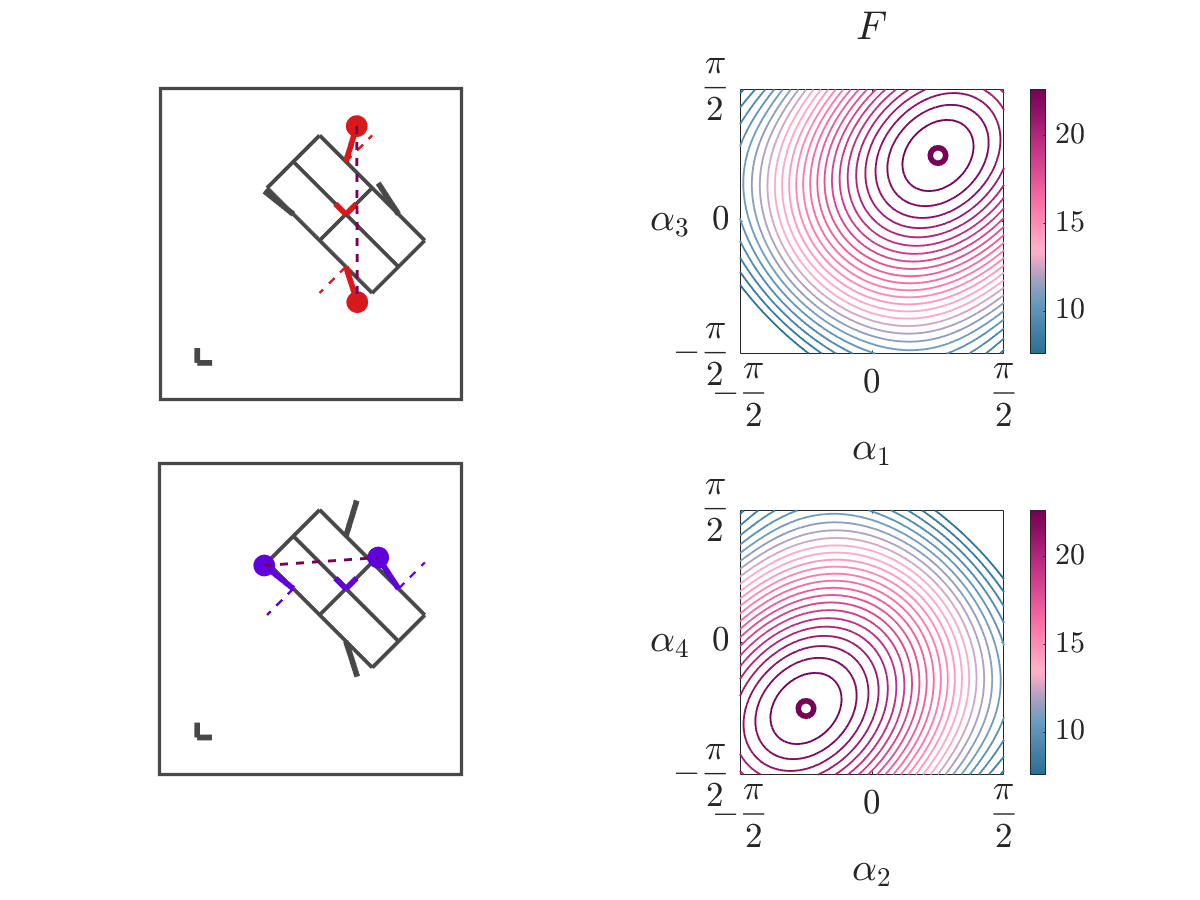

% spacing horizontally/along-X: 600 if just plot, 750 if with colorbar
% spacing vertically/along-Y: 600 if just plot, 750 if with colorbar
f = figure('units', 'pixels', 'position', [0 0 1350 1200], 'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 2, 2, "TileSpacing", "compact", "Padding", "compact");
tlF = tiledlayout(tl, 2, 1, "TileSpacing", "compact", "Padding", "compact");
tlF.Layout.Tile = 2; tlF.Layout.TileSpan = [2, 1]; % place the F-plots along the second column (span the whole column by setting the correct span)
axQ = cell(1, numel(sIdx)); axF = cell(1, numel(sIdx));
for i = 1:numel(sIdx)

    % PLOT ROBOT CONFIGURATION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    axQ{i} = nexttile(tl); hold(axQ{i}, "on"); box(axQ{i}, "on");
    % plot the body
    % ... first the body links
    % ... then the body frame
    quiver(axQ{i}, pltBodyX, pltBodyY, pltBodyU, pltBodyV,...
        "LineStyle", '-', "LineWidth", lW_b, "Color", paramColor, ...
        "AutoScale", "off", "ShowArrowHead", "off");
    hold on; axis(axQ{i}, "equal"); 
    quiver(axQ{i}, bodyFrameX, bodyFrameY, ...
        frame_scale*bodyFrameU, frame_scale*bodyFrameV,...
        "LineStyle", '-', "LineWidth", lW, "Color", stanceColor{i}, ...
        "AutoScale", "off", "ShowArrowHead", "off");
    % plot a origin frame
    quiver(axQ{i}, zeros(1, 2), zeros(1, 2), ...
        frame_scale*[1, 0], frame_scale*[0, 1],...
        "LineStyle", '-', "LineWidth", lW, "Color", originColor, ...
        "AutoScale", "off", "ShowArrowHead", "off");
    % iterate and plot limbs
    % ... @current iteration, check if the current limb belongs to the
    % ... submanifold
    % ... if it does, then plot it with stance phase color, scatter foot
    % ... tip to indicate nonslip/pin/revolute joint contact, and plot the
    % ... limb swing angle origin position
    % ... if it is NOT a part of the cs, then just quiver out the limb with
    % ... swing phase color
    for m = 1:numLimbs
        switch sIdx(logical(sum(cs(sIdx, :) == m, 2))) == sIdx(i)
            case 1 % current limb is a part of the cs
                quiver(axQ{i}, pltLimbX(m), pltLimbY(m), pltLimbU(m), pltLimbV(m), ...
                    "LineStyle", "-", "LineWidth", lW, "Color", limbStanceColor{m}, ...
                    "AutoScale", "off", "ShowArrowHead", "off");
                scatter(axQ{i}, footX(m), footY(m), circS, limbStanceColor{m}, "filled");
                quiver(axQ{i}, pltLimbX0(m), pltLimbY0(m), pltLimbU0(m), pltLimbV0(m), ...
                    "LineStyle", "--", "LineWidth", lW_r, "Color", limbStanceColor{m}, ...
                    "AutoScale", "off", "ShowArrowHead", "off");
            case 0 % current limb is NOT a part of the cs
                quiver(axQ{i}, pltLimbX(m), pltLimbY(m), pltLimbU(m), pltLimbV(m), ...
                    "LineStyle", "-", "LineWidth", lW, "Color", limbSwingColor, ...
                    "AutoScale", "off", "ShowArrowHead", "off");
        end
    end
    % plot the inter-leg vector between the stancing limbs
    quiver(axQ{i}, pltInterLimbX{i}, pltInterLimbY{i}, pltInterLimbU{i}, pltInterLimbV{i}, ...
        "LineStyle", "--", "LineWidth", lW_kq, "Color", [cmap_custom(end, :), 0.5], ...
        "AutoScale", "off", "ShowArrowHead", "off");
    % updates plot boxes and limits
    set(axQ{i}, 'xTick',[]); set(axQ{i}, 'yTick',[]); axis(axQ{i}, "equal");
    axis(axQ{i}, [limX, limY]); axQ{i}.LineWidth = 2*boxW;
    axQ{i}.XColor = paramColor; axQ{i}.YColor = paramColor;
    set(axQ{i},'Color', ones(1, 3));

    % PLOT THE F-SCALAR FIELDS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    axF{i} = nexttile(tlF); hold(axF{i}, "on"); box(axF{i}, "on");
    contour(axF{i}, ai, aj, F_sweep{i}, cLvl,'LineWidth',lW_c+1);
    axis(axF{i}, "equal", "tight"); hold(axF{i}, "on"); view(axF{i}, 2);
    contour(axF{i}, ai, aj, F_sweep{i}, Fthresh{i}*ones(1, 2), 'k--', 'LineWidth', lW_c+2);
    scatter(axF{i}, nalpha_mn_atSup{i}(1), nalpha_mn_atSup{i}(2), 0.5*circS, ...
                    'MarkerEdgeColor', cmap_custom(end, :), 'MarkerFaceColor', 'none', ...
                    'LineWidth', lW);
    % scatter(axF{i}, nalpha_mn_atInf{i}(1), nalpha_mn_atInf{i}(2), 0.5*circS, ...
    %                 'MarkerEdgeColor', cmap_custom(1, :), 'MarkerFaceColor', 'none', ...
    %                 'LineWidth', lW);
    colormap(axF{i}, cmap_custom); colorbar(axF{i}, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
    set(get(axF{i}, 'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
    xticks(axF{i}, xtickval); yticks(axF{i}, ytickval);
    xticklabels(axF{i}, xticklab);
    yticklabels(axF{i}, xticklab);
    xlabel(axF{i}, ['$$\alpha_{' num2str(cs(sIdx(i), 1)) '}$$'], FontSize=labelFS); 
    ylabel(axF{i}, ['$$\alpha_{' num2str(cs(sIdx(i), 2)) '}$$'], FontSize=labelFS);
    axF{i}.XAxis.FontSize = tickFS; axF{i}.YAxis.FontSize = tickFS; set(axF{i}, 'Color', col_backg);
    xlim(axF{i}, xlimits); ylim(axF{i}, ylimits); %axF{i}.XColor = stanceColor{i}; axF{i}.YColor = stanceColor{i};
end
title(tl, '', FontSize=titleFS); title(tlF, '$$F$$', 'Interpreter', 'latex', FontSize=titleFS);

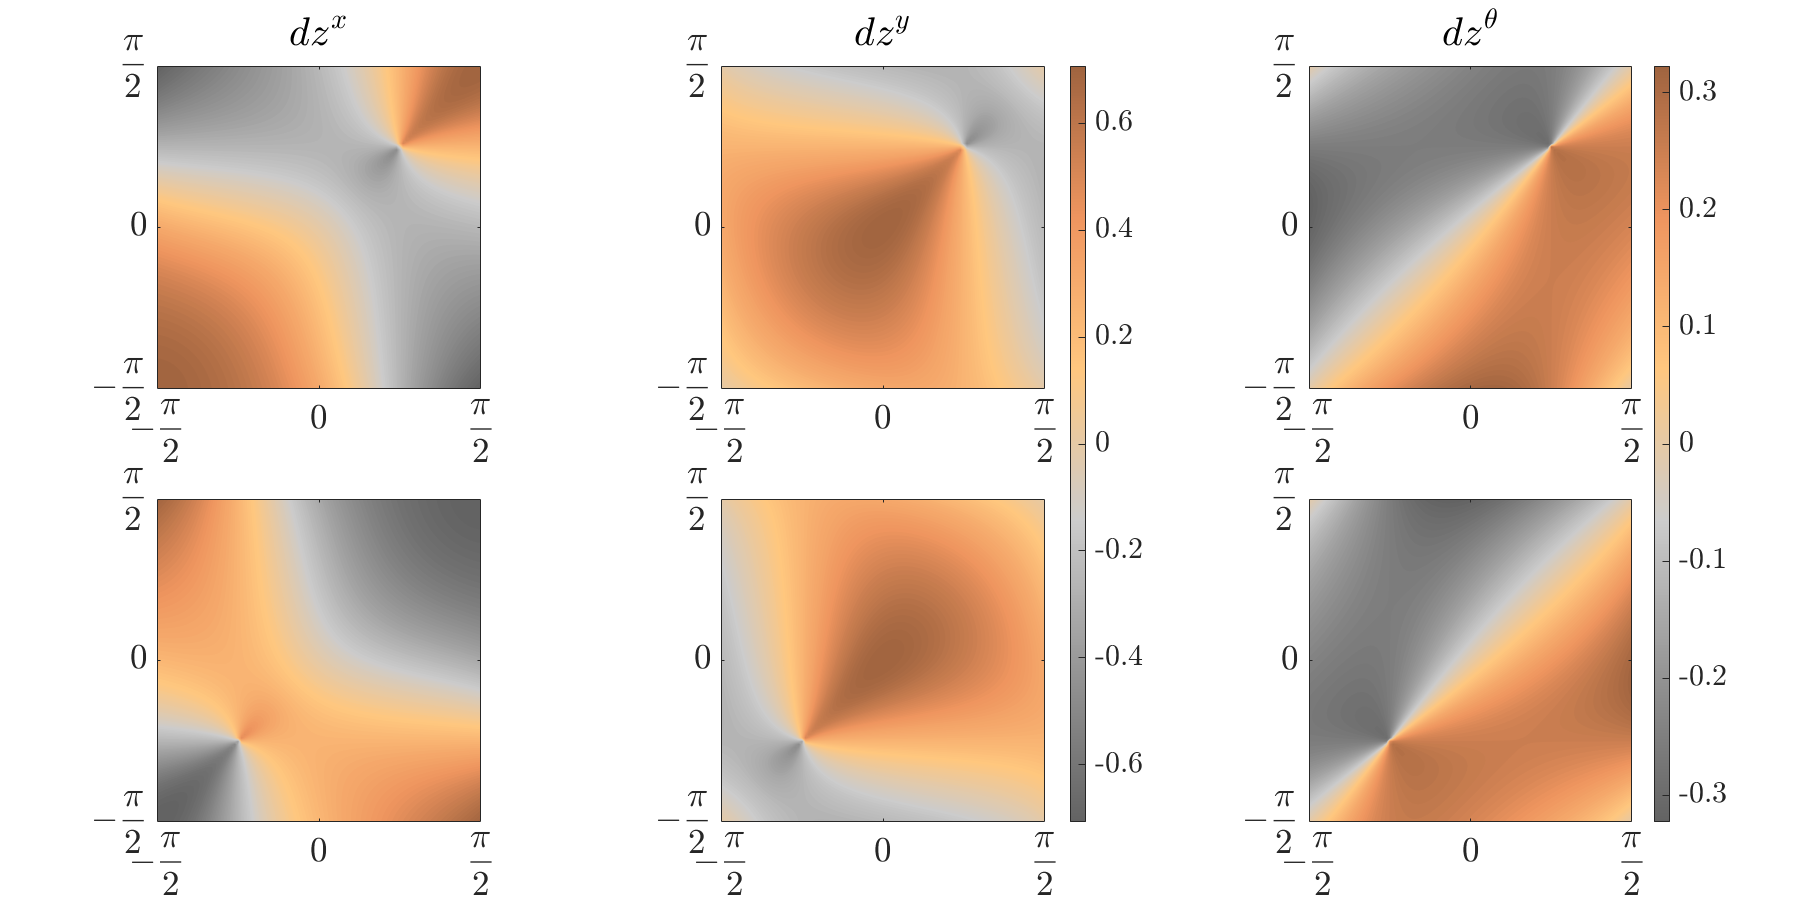

componentTxt = {'x', 'y', '\theta'};
f = figure('units', 'pixels', 'position', [0 0 1800 900], 'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 2, 3, "TileSpacing", "compact", "Padding", "compact");
tlXY = tiledlayout(tl, 2, 2, "TileSpacing", "compact", "Padding", "compact");
tlXY.Layout.Tile = 1; tlXY.Layout.TileSpan = [2, 2];
ax = cell(2, 3);
for k = 1:numel(sIdx) % iterate over each contact state
    for iComps = 1:3 % iterate over the SE(2) components
        switch iComps
            case {1, 2}
                ax{k, iComps} = nexttile(tlXY);
            case 3
                ax{k, iComps} = nexttile(tl);
        end
        contourf(ax{k, iComps}, ai, aj, dzSweep{k}{iComps}, cfLvl, 'LineStyle', 'none', 'FaceAlpha', fA);
        axis equal tight; hold on;
        contour(ax{k, iComps}, ai, aj, F_sweep{k}, Fthresh{k}*ones(1, 2), 'k--', 'LineWidth', lW_c+2);
        colormap(ax{k, iComps}, CUB);
        switch iComps
            case {1, 2}
                clim(ax{k, iComps}, transLimits);
            case 3
                clim(ax{k, iComps}, rotLimits);
        end
        if iComps ~= 1 && k == 2
            cb = colorbar('TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
            cb.Layout.Tile = 'east';
        end
        set(get(ax{k, iComps},'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
        if k == 1
            title(ax{k, iComps}, ['$$dz^{' componentTxt{iComps} '}$$'], 'Color', 'k', 'Interpreter', 'latex', FontSize=titleFS);
        end
        xticks(ax{k, iComps}, xtickval); yticks(ax{k, iComps}, ytickval);
        xticklabels(ax{k, iComps}, xticklab); yticklabels(ax{k, iComps}, yticklab);
        ax{k, iComps}.XAxis.FontSize = tickFS; ax{k, iComps}.YAxis.FontSize = tickFS;
        xlim(xlimits); ylim(ylimits);
    end
end

addpath 'Data'\ 'Utility Functions'\; 
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslipQuadMobility.mat');

set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Lateral body-bending quadruped case:

dnumLite = floor(0.03*dnum);
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :);
na_bX = bodyScalingParam(end); na_bY = bodyScalingParam(end);
na = limbScalingParam(end);
nl = 1; bodyLength = double(subs(bodyLength, l, nl));
ngamma = linspace(gammaParam(1), gammaParam(2), dnumLite); % GENERATE VARYING PARAMETER
F_prctRm = 15;
nalpha = rand(4, 1, "double")*(limbAngleParam(2) - limbAngleParam(1)) ...
    + limbAngleParam(1); % generate random limb angles
nalpha0 = limbAngleParam(end);
% nx = bodyLength; ny = bodyLength; ntheta = pi/4;
nx = 0; ny = 0; ntheta = 0;

bodyColor = col(end, :); limbSwingColor = bodyColor; originColor = bodyColor;
limbStanceColor = cell(1, numLimbs); stanceColor = cell(1, numel(sIdx));
paramColor = interpColorAndCondition( ...
    (1:size(bMorphCol_bid, 1))', bMorphCol_bid, ... % X, V
    linspace(1, size(bMorphCol_bid, 1), dnumLite) ... % Xq
                                        ); 

gbody = fh_e__b(nx, ny, ntheta);
bodyX = gbody'*x_sel; bodyY = gbody'*y_sel; bodyTh = gbody'*theta_sel;

bodyFrameX = bodyX*ones(1, 2); bodyFrameY = bodyY*ones(1, 2);
bodyFrameU = x_sel'*rot_SE2(bodyTh)*Cxy'; bodyFrameV = y_sel'*rot_SE2(bodyTh)*Cxy';

pltBodyX = cell(1, numel(ngamma)); pltBodyY = cell(1, numel(ngamma)); 
pltBodyU = cell(1, numel(ngamma)); pltBodyV = cell(1, numel(ngamma)); 
pltLimbX = cell(1, numel(ngamma)); pltLimbY = cell(1, numel(ngamma)); 
pltLimbU = cell(1, numel(ngamma)); pltLimbV = cell(1, numel(ngamma));
pltLimbX0 = cell(1, numel(ngamma)); pltLimbY0 = cell(1, numel(ngamma)); 
pltLimbU0 = cell(1, numel(ngamma)); pltLimbV0 = cell(1, numel(ngamma)); 
footX = cell(1, numel(ngamma)); footY = cell(1, numel(ngamma));
pltInterLimbX = cell(1, numel(ngamma)); pltInterLimbY = cell(1, numel(ngamma)); 
pltInterLimbU = cell(1, numel(ngamma)); pltInterLimbV = cell(1, numel(ngamma));
for p = 1:numel(ngamma)
    if p == 1
        xPts = 0; yPts = 0;
    end
    pltBodyX{p} = []; pltBodyY{p} = []; pltBodyU{p} = []; pltBodyV{p} = []; 
    pltLimbX{p} = []; pltLimbY{p} = []; pltLimbU{p} = []; pltLimbV{p} = [];
    pltLimbX0{p} = []; pltLimbY0{p} = []; pltLimbU0{p} = []; pltLimbV0{p} = []; 
    footX{p} = []; footY{p} = [];
    for i = 1:numLimbs
        pltBodyX{p} = [pltBodyX{p}, bodyX]; pltBodyY{p} = [pltBodyY{p}, bodyY]; 
        pltBodyU{p} = [pltBodyU{p}, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*x_sel];
        pltBodyV{p} = [pltBodyV{p}, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*y_sel];
        pltBodyX{p} = [pltBodyX{p}, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*x_sel)'];
        pltBodyY{p} = [pltBodyY{p}, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*y_sel)'];
        pltBodyU{p} = [pltBodyU{p}, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*x_sel)'];
        pltBodyV{p} = [pltBodyV{p}, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*y_sel)'];
        pltLimbX{p} = [pltLimbX{p}, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*x_sel];
        pltLimbY{p} = [pltLimbY{p}, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta)'*y_sel];
        pltLimbU{p} = [pltLimbU{p}, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, nalpha(i))'*x_sel];
        pltLimbV{p} = [pltLimbV{p}, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, nalpha(i))'*y_sel];
        pltLimbX0{p} = [pltLimbX0{p}, pltLimbX{p}(i)]; pltLimbY0{p} = [pltLimbY0{p}, pltLimbY{p}(i)];
        pltLimbU0{p} = [pltLimbU0{p}, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, 0)'*x_sel];
        pltLimbV0{p} = [pltLimbV0{p}, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, 0)'*y_sel];
        footX{p} = [footX{p}, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, nalpha(i))'*x_sel]; 
        footY{p} = [footY{p}, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma(p), nx, ny, ntheta, nalpha(i))'*y_sel];
        if p == 1
            limbStanceColor{i} = col(sIdx(logical(sum(cs(sIdx, :) == i, 2))), :);
        end
    end
    pltInterLimbX{p} = cell(1, numel(sIdx)); pltInterLimbY{p} = cell(1, numel(sIdx)); 
    pltInterLimbU{p} = cell(1, numel(sIdx)); pltInterLimbV{p} = cell(1, numel(sIdx));
    for k = 1:numel(sIdx)
        m = cs(sIdx(k), 1); n = cs(sIdx(k), 2);
        pltInterLimbX{p}{k} = footX{p}(m); pltInterLimbY{p}{k} = footY{p}(m);
        pltInterLimbU{p}{k} = footX{p}(n)-footX{p}(m);
        pltInterLimbV{p}{k} = footY{p}(n)-footY{p}(m);
        if p == 1
            stanceColor{k} = col(sIdx(k), :);
        end
    end
    xPts = [xPts, pltBodyX{p}, pltLimbX{p}, footX{p}]; 
    yPts = [yPts, pltBodyY{p}, pltLimbY{p}, footY{p}];
end

limX = [min(xPts), max(xPts)]; limY = [min(yPts), max(yPts)];
bodyPlotThresh = 0.25*bodyLength*[-1 1];
limX = limX+bodyPlotThresh; limY = limY+bodyPlotThresh;
scal = 30*bodyLength/4; 
scaleDraw = max([diff(limX),diff(limY)])/scal;
lW = 1.2/scaleDraw; lW_r = 0.5/scaleDraw; lW_b = 0.8/scaleDraw;
lW_kq = 0.6/scaleDraw; lW_qf = 0.8/scaleDraw;
frame_scale = 0.10*bodyLength;
circS = 75/scaleDraw;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
nalpha_mn_atInf = cell(1, numel(ngamma));
nalpha_mn_atSup = cell(1, numel(ngamma));
F_sweep = cell(1, numel(ngamma)); 
Flim = cell(1, numel(ngamma));         
FParam = cell(1, numel(ngamma));  
Fthresh = cell(1, numel(ngamma));                   
dzSweep = cell(1, numel(ngamma)); 
dzParam = cell(1, numel(ngamma));
for p = 1:numel(ngamma)
    nalpha_mn_atInf_NOW = cell(size(sIdx));
    nalpha_mn_atSup_NOW = cell(size(sIdx));
    F_sweep_NOW = cell(size(sIdx)); 
    Flim_NOW = [inf, -inf];         
    FParam_NOW = cell(size(sIdx));  
    Fthresh_NOW = cell(size(sIdx)); 
    dzSweep_NOW = cell(size(sIdx)); 
    dzParam_NOW = cell(size(sIdx));
    for i = 1:numel(sIdx)
        % ... squared inter-foot (stancing) distance: F
        % ... ... current function to compute F
        % ... ... get the sweep for the F scalar field
        % ... ... obtain the F parameter variable (stores limits and nominal
        % ... ... value)
        % ... ... remove 15% of the F-range about the singularity at the
        % ... ... infimum
        fFnow = fF_i{sIdx(i)};
        F_sweep_NOW{i} = fFnow(na_bX, na_bY, na, nl, ngamma(p), ai, aj);
        nalpha_mn_atInf_NOW{i} = fmincon( ...
                    @(x) fFnow(na_bX, na_bY, na, nl, ngamma(p), x(1), x(2)), ... % function setup
                    nalpha0*ones(1, 2), ... % ic at limb angle origin
                    [], [], [], [], ... % no equality or inequality constraints
                    limbAngleParam(1)*ones(1, 2), ...
                    limbAngleParam(2)*ones(1, 2), ... % pi range, and pi/2 symmetric amplitude bounds
                    [],... % no nonlinear constraints
                    optimoptions("fmincon", "Display", "none"));
        Finf_now = fFnow(na_bX, na_bY, na, nl, ngamma(p),...
                        nalpha_mn_atInf_NOW{i}(1), nalpha_mn_atInf_NOW{i}(2));
        nalpha_mn_atSup_NOW{i} = fmincon( ... % find supremum location
                    @(x) -fFnow(na_bX, na_bY, na, nl, ngamma(p), x(1), x(2)), ...
                    nalpha0*ones(1, 2), ... % ic
                    [], [], [], [], ... 
                    limbAngleParam(1)*ones(1, 2), ...
                    limbAngleParam(2)*ones(1, 2), ...
                    [],... 
                    optimoptions("fmincon", "Display", "none"));
        Fsup_now = fFnow(na_bX, na_bY, na, nl, ngamma(p), ...
                        nalpha_mn_atSup_NOW{i}(1), nalpha_mn_atSup_NOW{i}(2));
        F0_now = fFnow(na_bX, na_bY, na, nl, ngamma(p), nalpha0, nalpha0);
        if Finf_now < Flim_NOW(1)
            Flim_NOW(1) = Finf_now;
        end % updated the color limits for the F values-- one set of limits for both cs
        if Fsup_now > Flim_NOW(2)
            Flim_NOW(2) = Fsup_now;
        end
        FParam_NOW{i} = [Finf_now, Fsup_now, F0_now]; 
        FrangeNow = Fsup_now-Finf_now; Fthresh_NOW{i} = Finf_now + F_prctRm/100*FrangeNow;
        idxThresh = F_sweep_NOW{i} < Fthresh_NOW{i}; % locations below the recommended threshold
        F_sweep_NOW{i}(idxThresh) = nan(  size(F_sweep_NOW{i}(idxThresh))  ); % set these locations to nan
        % ... compute the stratified panels
        % ... ... current function to compute dz
        fdznow = fdz_i{sIdx(i)}; dzSweep_NOW{i} = cell(3, 1);
        dzRowiseComponents = fdznow(na_bX, na_bY, na, nl, ngamma(p), ...
            reshape(ai, [1, numel(ai)]), reshape(aj, [1, numel(aj)... % make the limb angle space row vectors
            ]));
        dzParam_NOW{i} = [min(dzRowiseComponents, [], 2), ...
                      max(dzRowiseComponents, [], 2), ...
                      fdznow(na_bX, na_bY, na, nl, ngamma(p), nalpha0, nalpha0)];
        if p == 1 && i == 1
                transArrX = dzParam_NOW{i}(1, 1:2);
                transArrY = dzParam_NOW{i}(2, 1:2);
                rotArr    = dzParam_NOW{i}(3, 1:2);
        else
                transArrX = [transArrX; dzParam_NOW{i}(1:2, 1:2)];
                transArrY = [transArrY; dzParam_NOW{i}(1:2, 1:2)];
                rotArr    = [rotArr, dzParam_NOW{i}(3, 1:2)];
        end
        for j = 1:size(dzRowiseComponents, 1)
            dzSweep_NOW{i}{j} = reshape(dzRowiseComponents(j, :), size(ai));
        end
    end
    % assign for each body morphing value
    nalpha_mn_atInf{p} = nalpha_mn_atInf_NOW;
    nalpha_mn_atSup{p} = nalpha_mn_atSup_NOW;
    F_sweep{p} = F_sweep_NOW; 
    Flim{p} = Flim_NOW;         
    FParam{p} = FParam_NOW;  
    Fthresh{p} = Fthresh_NOW;                   
    dzSweep{p} = dzSweep_NOW; 
    dzParam{p} = dzParam_NOW;
end


ans =

     []


ans =

     []


ans =

     []


ans =

     []


ans =

     []


ans =

     []



[transLimits, rotLimits] = se2limits(transArrX, transArrY, rotArr); % common limits for all body morphing values

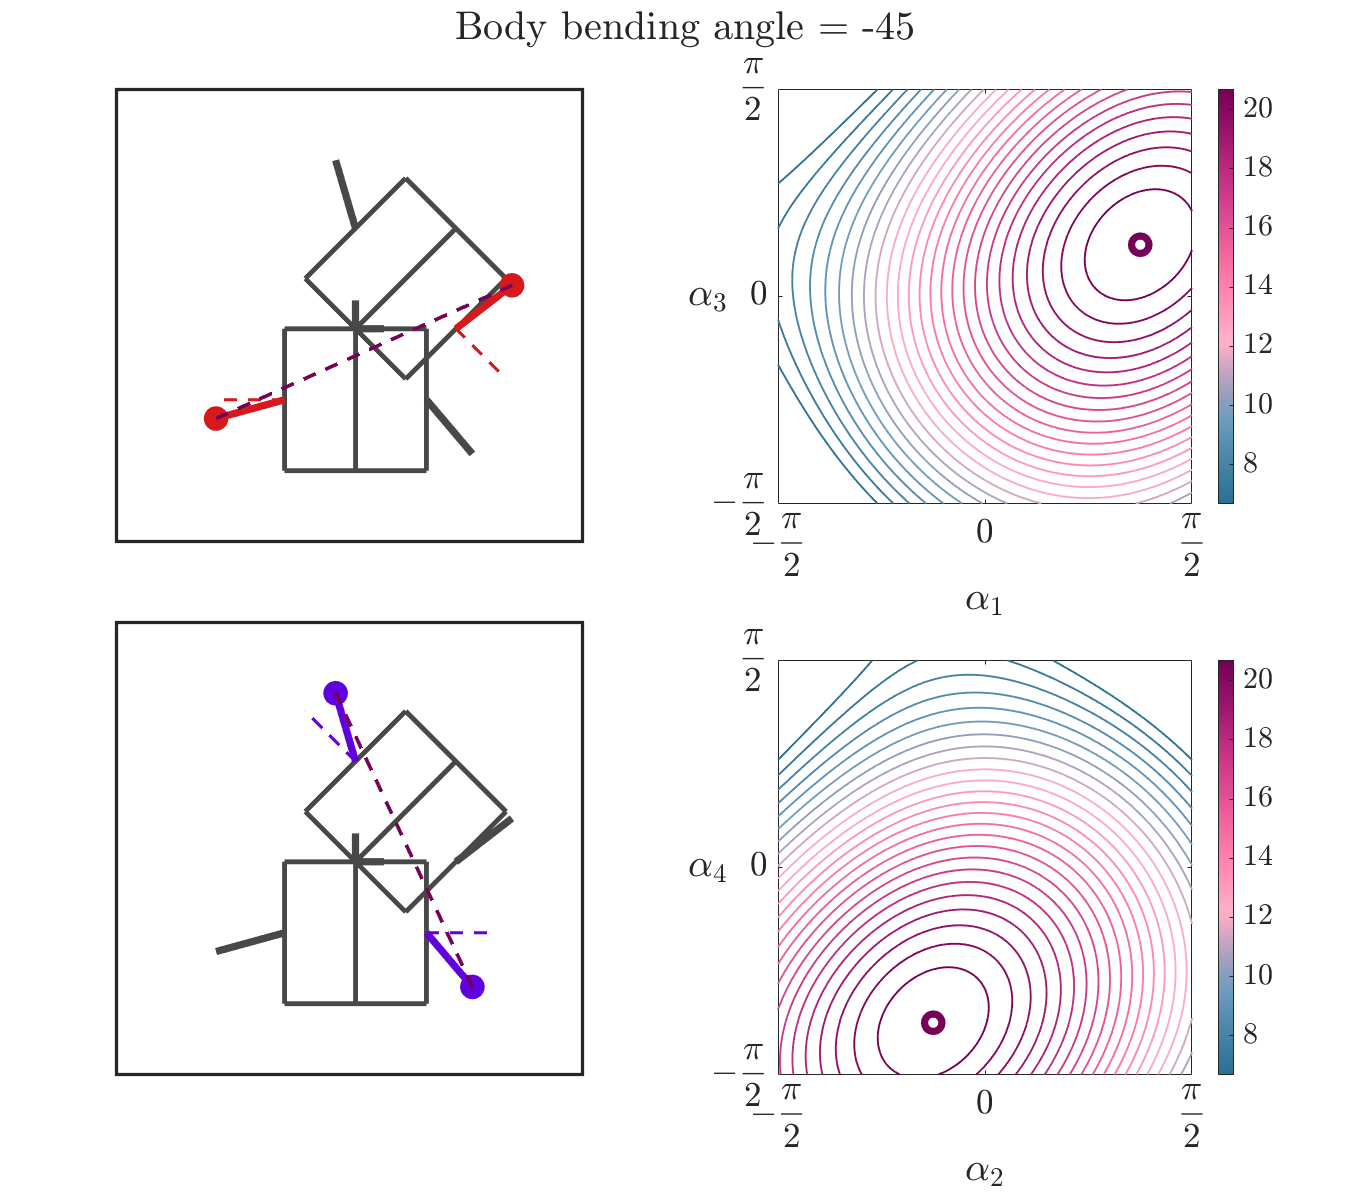

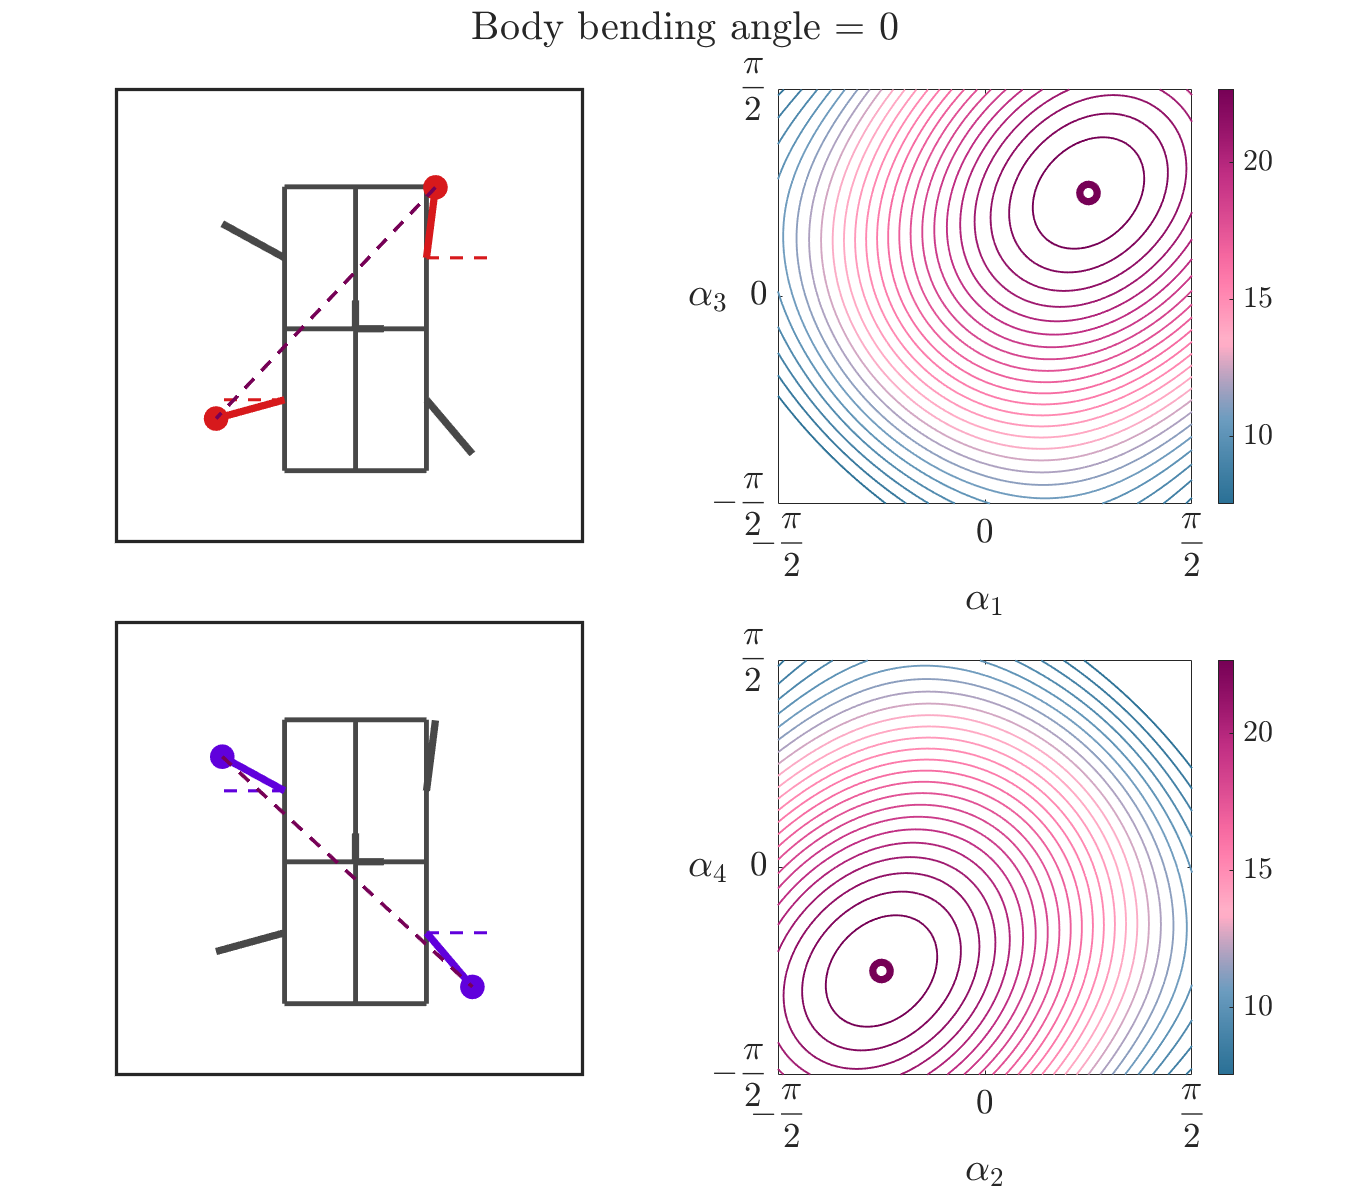

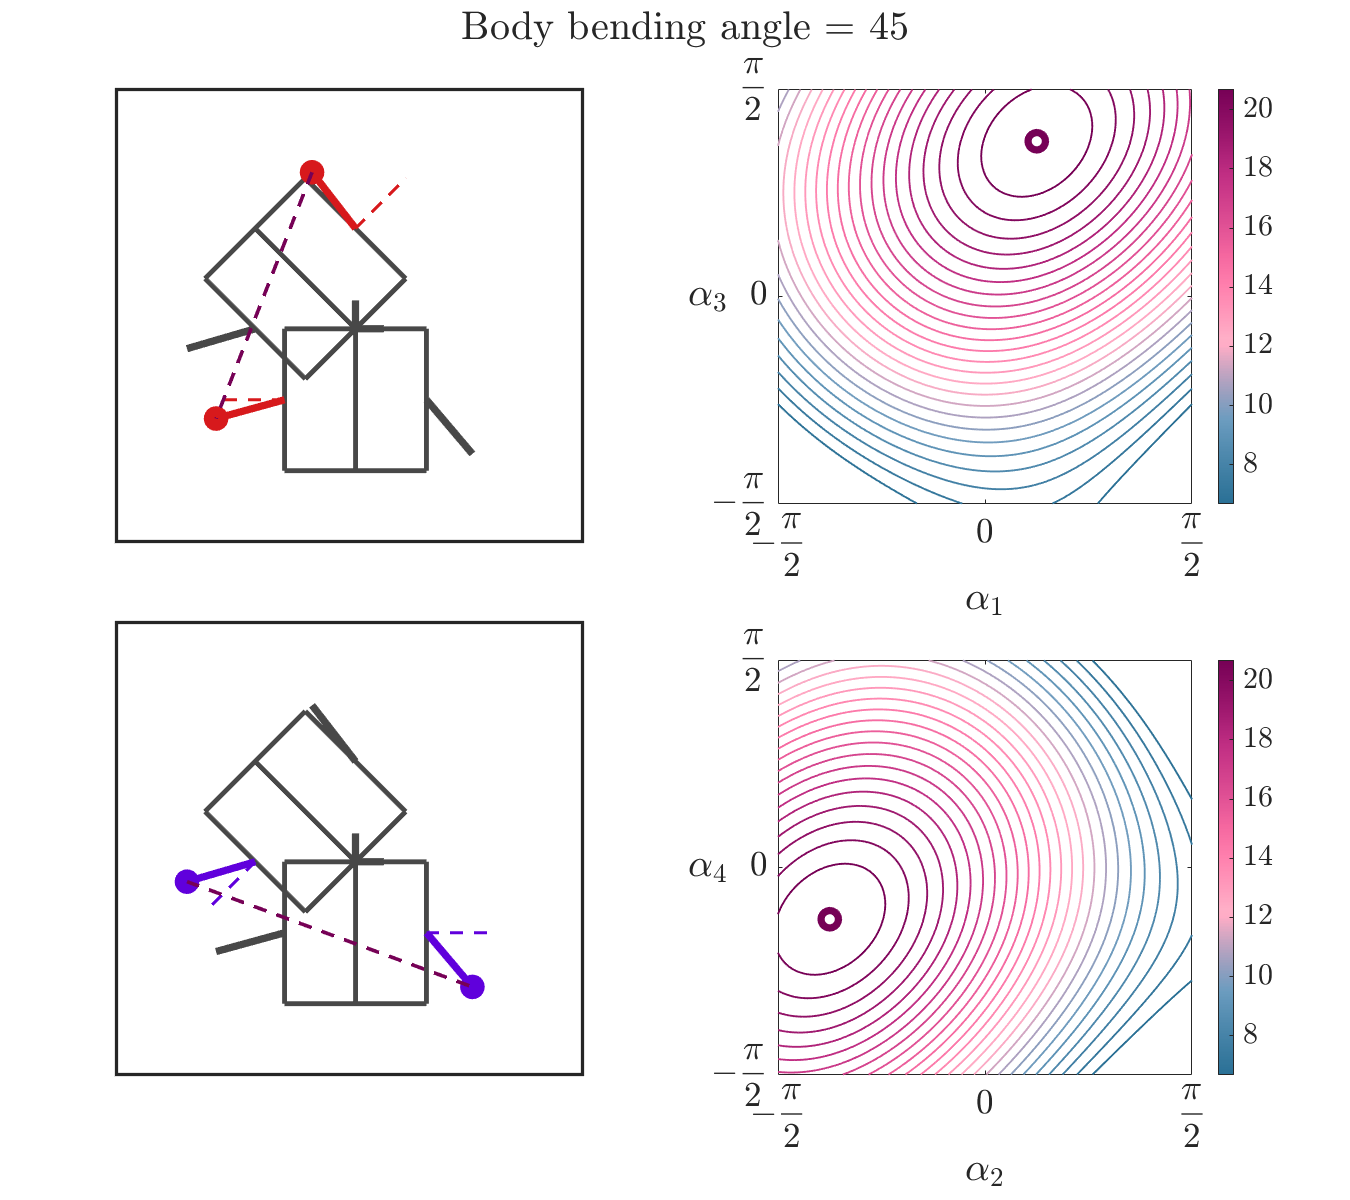

for p = 1:numel(ngamma)
    f = figure('units', 'pixels', 'position', [0 0 1350 1200], 'Color','w'); set(f,'Visible','on');
    tl = tiledlayout(f, 2, 2, "TileSpacing", "compact", "Padding", "compact");
    tlF = tiledlayout(tl, 2, 1, "TileSpacing", "compact", "Padding", "compact");
    tlF.Layout.Tile = 2; tlF.Layout.TileSpan = [2, 1];
    axQ = cell(1, numel(sIdx)); axF = cell(1, numel(sIdx));
    for i = 1:numel(sIdx)
        axQ{i} = nexttile(tl); hold(axQ{i}, "on"); box(axQ{i}, "on");
        quiver(axQ{i}, pltBodyX{p}, pltBodyY{p}, pltBodyU{p}, pltBodyV{p},...
            "LineStyle", '-', "LineWidth", lW_b, "Color", bodyColor, ...
            "AutoScale", "off", "ShowArrowHead", "off");
        % h{end+1} = quiver(axQ{i}, pltBodyX{p}, pltBodyY{p}, pltBodyU{p}, pltBodyV{p},...
        %     "LineStyle", '-.', "LineWidth", lW_kq, "Color", paramColor(p, :), ...
        %     "AutoScale", "off", "ShowArrowHead", "off"); % plot with param color overlay
        for m = 1:numLimbs
            switch sIdx(logical(sum(cs(sIdx, :) == m, 2))) == sIdx(i)
                case 1
                    quiver(axQ{i}, pltLimbX{p}(m), pltLimbY{p}(m), pltLimbU{p}(m), pltLimbV{p}(m), ...
                        "LineStyle", "-", "LineWidth", lW, "Color", limbStanceColor{m}, ...
                        "AutoScale", "off", "ShowArrowHead", "off");
                    scatter(axQ{i}, footX{p}(m), footY{p}(m), circS, limbStanceColor{m}, ...
                        "filled");
                    quiver(axQ{i}, pltLimbX0{p}(m), pltLimbY0{p}(m), pltLimbU0{p}(m), pltLimbV0{p}(m), ...
                        "LineStyle", "--", "LineWidth", lW_r, "Color", limbStanceColor{m}, ...
                        "AutoScale", "off", "ShowArrowHead", "off");
                case 0
                    quiver(axQ{i}, pltLimbX{p}(m), pltLimbY{p}(m), pltLimbU{p}(m), pltLimbV{p}(m), ...
                        "LineStyle", "-", "LineWidth", lW, "Color", limbSwingColor, ...
                        "AutoScale", "off", "ShowArrowHead", "off");
            end
        end
        quiver(axQ{i}, pltInterLimbX{p}{i}, pltInterLimbY{p}{i}, pltInterLimbU{p}{i}, pltInterLimbV{p}{i}, ...
            "LineStyle", "--", "LineWidth", lW_kq, "Color", cmap_custom(end, :), ...
            "AutoScale", "off", "ShowArrowHead", "off");
        quiver(axQ{i}, bodyFrameX, bodyFrameY, ...
            frame_scale*bodyFrameU, frame_scale*bodyFrameV,...
            "LineStyle", '-', "LineWidth", lW, "Color", stanceColor{i}, ...
            "AutoScale", "off", "ShowArrowHead", "off");
        quiver(axQ{i}, zeros(1, 2), zeros(1, 2), ... % body and origin frames
            frame_scale*[1, 0], frame_scale*[0, 1],...
            "LineStyle", '-', "LineWidth", lW, "Color", originColor, ...
            "AutoScale", "off", "ShowArrowHead", "off");
        set(axQ{i}, 'xTick',[]); set(axQ{i}, 'yTick',[]); axis(axQ{i}, "equal");
        axis(axQ{i}, [limX, limY]); axQ{i}.LineWidth = 2*boxW;
        set(axQ{i},'Color', ones(1, 3));
        % axQ{i}.XColor = paramColor(p, :); axQ{i}.YColor = paramColor(p, :); % not using "paramColor" right now

        % PLOT THE F-SCALAR FIELDS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        axF{i} = nexttile(tlF); hold(axF{i}, "on"); box(axF{i}, "on");
        contour(axF{i}, ai, aj, F_sweep{p}{i}, cLvl,'LineWidth',lW_c+1);
        axis(axF{i}, "equal", "tight"); hold(axF{i}, "on"); view(axF{i}, 2);
        contour(axF{i}, ai, aj, F_sweep{p}{i}, Fthresh{p}{i}*ones(1, 2), 'k--', 'LineWidth', lW_c+2);
        scatter(axF{i}, nalpha_mn_atSup{p}{i}(1), nalpha_mn_atSup{p}{i}(2), 0.5*circS, ...
                        'MarkerEdgeColor', cmap_custom(end, :), 'MarkerFaceColor', 'none', ...
                        'LineWidth', lW);
        % scatter(axF{i}, nalpha_mn_atInf{i}(1), nalpha_mn_atInf{i}(2), 0.5*circS, ...
        %                 'MarkerEdgeColor', cmap_custom(1, :), 'MarkerFaceColor', 'none', ...
        %                 'LineWidth', lW);
        colormap(axF{i}, cmap_custom); colorbar(axF{i}, 'TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
        set(get(axF{i}, 'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
        xticks(axF{i}, xtickval); yticks(axF{i}, ytickval);
        xticklabels(axF{i}, xticklab);
        yticklabels(axF{i}, xticklab);
        xlabel(axF{i}, ['$$\alpha_{' num2str(cs(sIdx(i), 1)) '}$$'], FontSize=labelFS); 
        ylabel(axF{i}, ['$$\alpha_{' num2str(cs(sIdx(i), 2)) '}$$'], FontSize=labelFS);
        axF{i}.XAxis.FontSize = tickFS; axF{i}.YAxis.FontSize = tickFS; set(axF{i}, 'Color', col_backg);
        xlim(axF{i}, xlimits); ylim(axF{i}, ylimits); %axF{i}.XColor = stanceColor{i}; axF{i}.YColor = stanceColor{i};
    end
    title(tl, ['Body bending angle = ' num2str(rad2deg(ngamma(p)))], ...
        'Interpreter', 'latex', "FontSize", titleFS);
    % if p == 1 % setup a colorbar to display the varying parameter
    %     colormap(f, bMorphCol_bid); clim([min(rad2deg(ngamma)) max(rad2deg(ngamma))]);
    %     cb = colorbar('Ticks', rad2deg(ngamma), 'TickLabels', string(rad2deg(ngamma)), ...
    %         'TickLabelInterpreter', 'latex'); cb.Layout.Tile = 'west';  cb.FontSize = tickFS;
    %     cb.Label.String = '$$\gamma$$'; cb.Label.Rotation = 0;
    %     cb.Label.Interpreter = 'latex'; cb.Label.FontSize = titleFS;
    % end
    drawnow(); 
    keyboard; % reset as soon as the plots are saved
    try
        clf(f); close(f);
    end
end

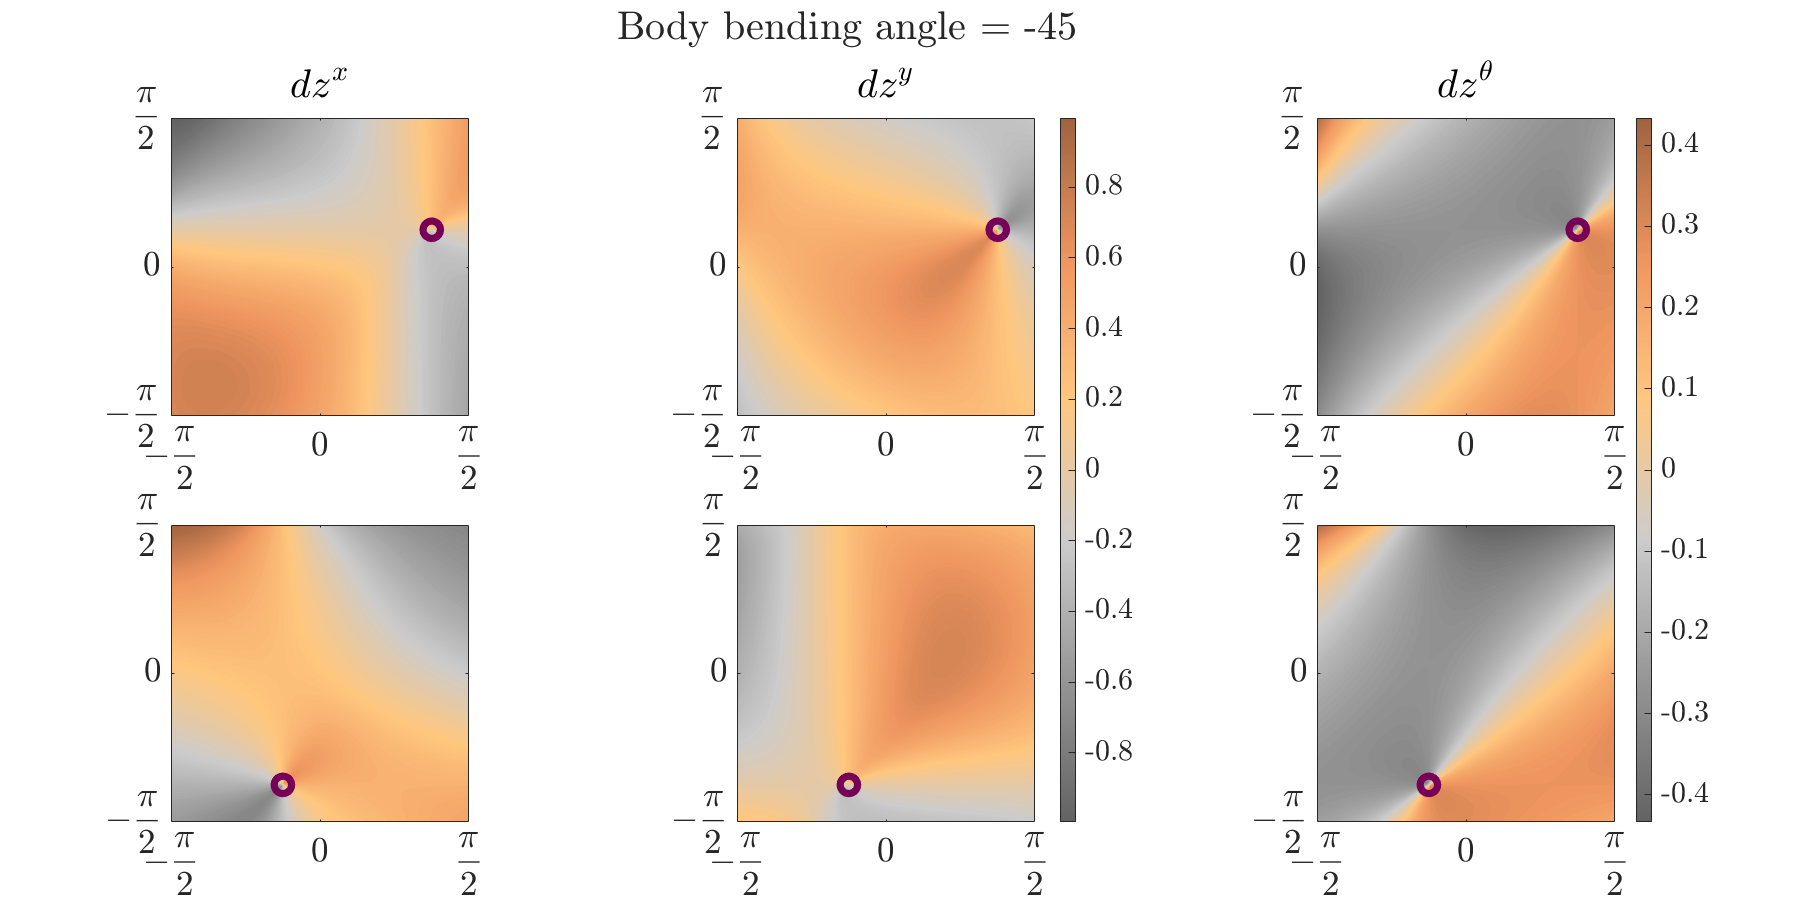

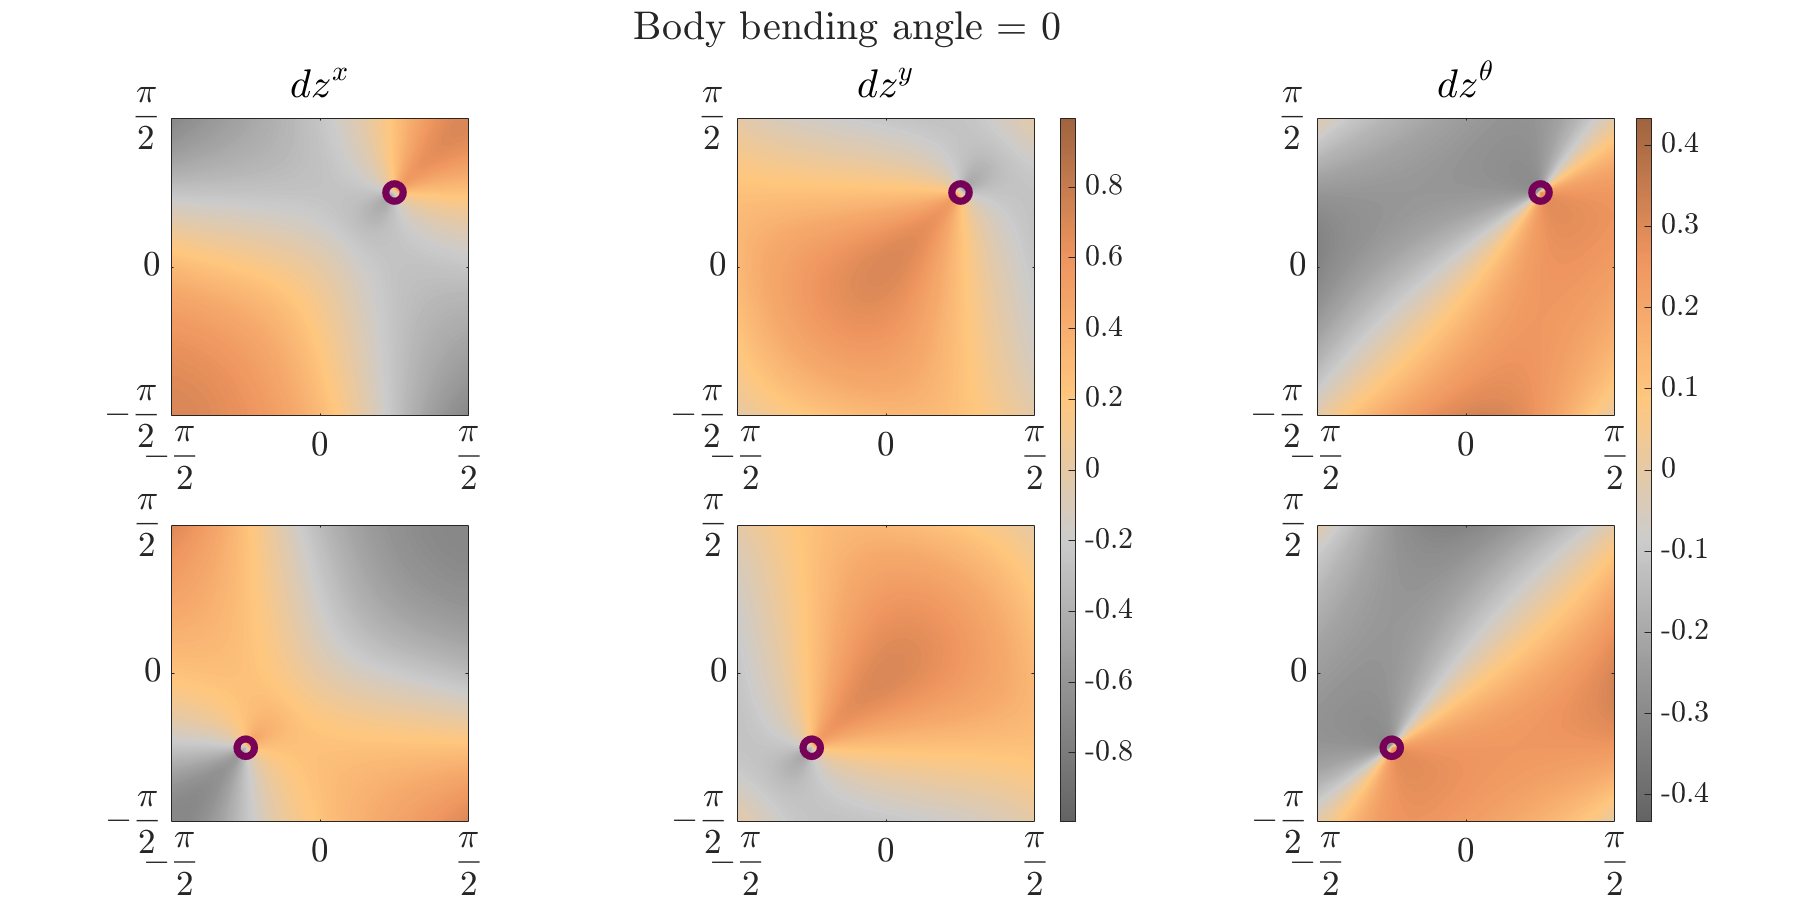

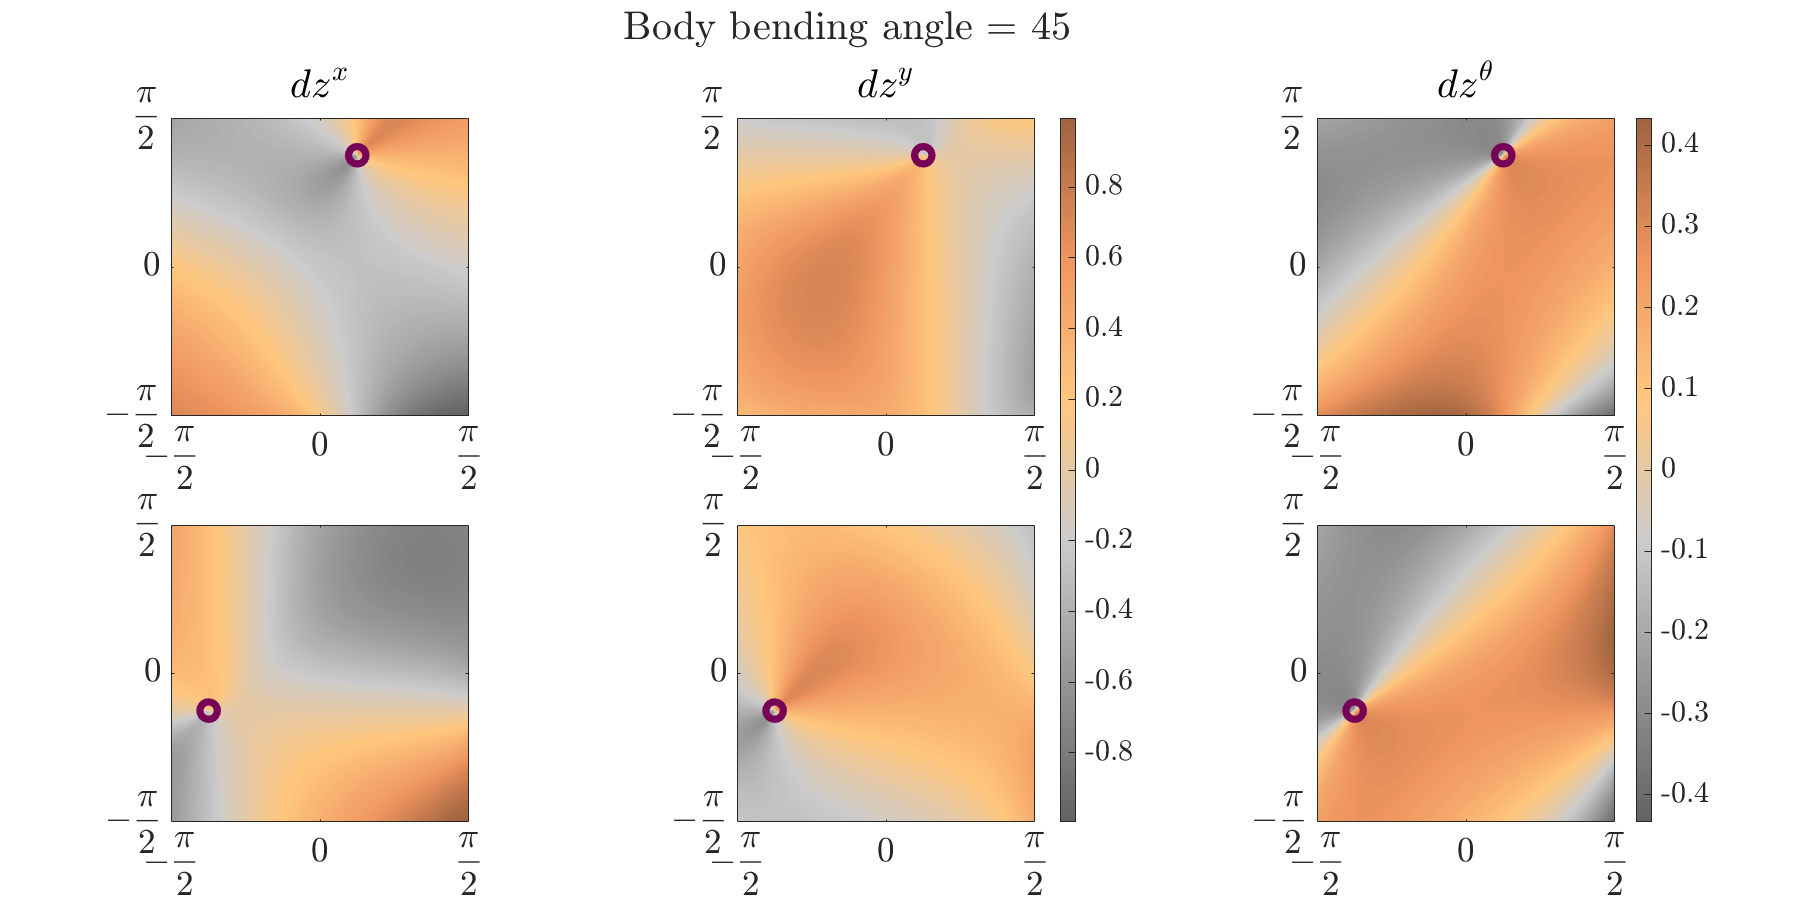

componentTxt = {'x', 'y', '\theta'};
for p = 1:numel(ngamma)
    f = figure('units', 'pixels', 'position', [0 0 1800 900], 'Color','w'); set(f,'Visible','on');
    tl = tiledlayout(f, 2, 3, "TileSpacing", "compact", "Padding", "compact");
    tlXY = tiledlayout(tl, 2, 2, "TileSpacing", "compact", "Padding", "compact");
    tlXY.Layout.Tile = 1; tlXY.Layout.TileSpan = [2, 2];
    ax = cell(2, 3);
    for k = 1:numel(sIdx) % iterate over each contact state
        for iComps = 1:3 % iterate over the SE(2) components
            switch iComps
                case {1, 2}
                    ax{k, iComps} = nexttile(tlXY);
                case 3
                    ax{k, iComps} = nexttile(tl);
            end
            contourf(ax{k, iComps}, ai, aj, dzSweep{p}{k}{iComps}, cfLvl, 'LineStyle', 'none', 'FaceAlpha', fA);
            axis equal tight; hold on;
            contour(ax{k, iComps}, ai, aj, F_sweep{p}{k}, Fthresh{p}{k}*ones(1, 2), 'k--', 'LineWidth', lW_c+2);
            scatter(ax{k, iComps}, nalpha_mn_atSup{p}{k}(1), nalpha_mn_atSup{p}{k}(2), 0.5*circS, ...
                        'MarkerEdgeColor', cmap_custom(end, :), 'MarkerFaceColor', 'none', ...
                        'LineWidth', lW);
            colormap(ax{k, iComps}, CUB);
            switch iComps
                case {1, 2}
                    clim(ax{k, iComps}, transLimits);
                case 3
                    clim(ax{k, iComps}, rotLimits);
            end
            if iComps ~= 1 && k == 2
                cb = colorbar('TickLabelInterpreter', 'latex', 'FontSize', cbarFS);
                cb.Layout.Tile = 'east';
            end
            set(get(ax{k, iComps},'YLabel'), 'rotation', 0, 'VerticalAlignment', 'middle');
            if k == 1
                title(ax{k, iComps}, ['$$dz^{' componentTxt{iComps} '}$$'], 'Color', 'k', 'Interpreter', 'latex', FontSize=titleFS);
            end
            xticks(ax{k, iComps}, xtickval); yticks(ax{k, iComps}, ytickval);
            xticklabels(ax{k, iComps}, xticklab); yticklabels(ax{k, iComps}, yticklab);
            ax{k, iComps}.XAxis.FontSize = tickFS; ax{k, iComps}.YAxis.FontSize = tickFS;
            xlim(xlimits); ylim(ylimits);
        end
    end
    title(tl, ['Body bending angle = ' num2str(rad2deg(ngamma(p)))], ...
        'Interpreter', 'latex', "FontSize", titleFS);
    drawnow(); 
    keyboard; % reset as soon as the plots are saved
    try
        clf(f); close(f);
    end
end